# Analyze Instron Data For Gels 

Code Updated Monday, August 15, 2022

By: Bo Bowman bo.h.bowman@gmail.com 

## Import Files 

%clear the MATLAB workspace & command window  
clear all; 
close all; 

%if you save it as .mlx, it will show the results live in the file. Click
%on the "output on right" or "output in line" icons to see the output. 
%if you save it as .m, the figures and graphs will automatically pop up in
%a separate new window. 

%As long as you opened the script (this file) and as long as the folder containg 
%the script also contains the data, then this should work: 
current_folder = pwd;

%INSTRUCTIONS: 
%Use the left hand "Current Folder" panel to navigate to the folder your
%script is in. OTHERWISE IT WILL NOT WORK
%Close excel before starting, otherwise it will count # of files as too
%many and throw back errors during the last part of the n loop of code. 
%Ensure that your data is properly re-formatted before using this code. 

%use Ctrl C to break. 

%Get information about what's inside your folder.
myfiles = dir(current_folder);
%Get the filenames and folders of all files and folders inside the folder
%of your choice.
filenames={myfiles(:).name}';
filefolders={myfiles(:).folder}';
%Get only those files that have a csv extension and their corresponding
%folders.
csvfiles=filenames(endsWith(filenames,'.csv'));
csvfolders=filefolders(endsWith(filenames,'.csv'));
%Make a cell array of strings containing the full file locations of the
%files.
files=fullfile(csvfolders,csvfiles);
number_of_files = length(files);

## Import Data & Provide Raw Graphs 

Filename: dummyfivesamples.csv

File 1 out of 2

num_samples_list =      1
     2
     3
     4
     5


indexes =            1
       25271
       69805
      116567
      166284


tensile_strain_index = 5

tensile_stress_index = 6

sample_number = 1

sample_number_check = 1

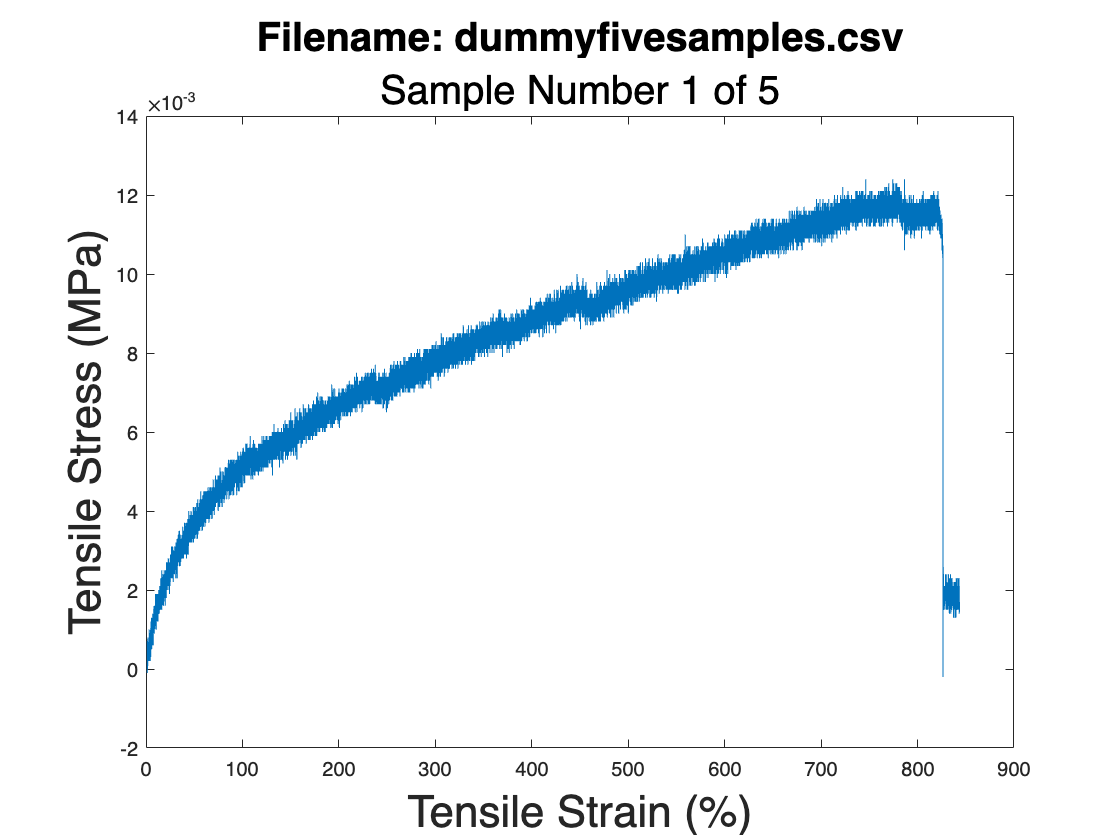

sample_number = 2

sample_number_check = 2

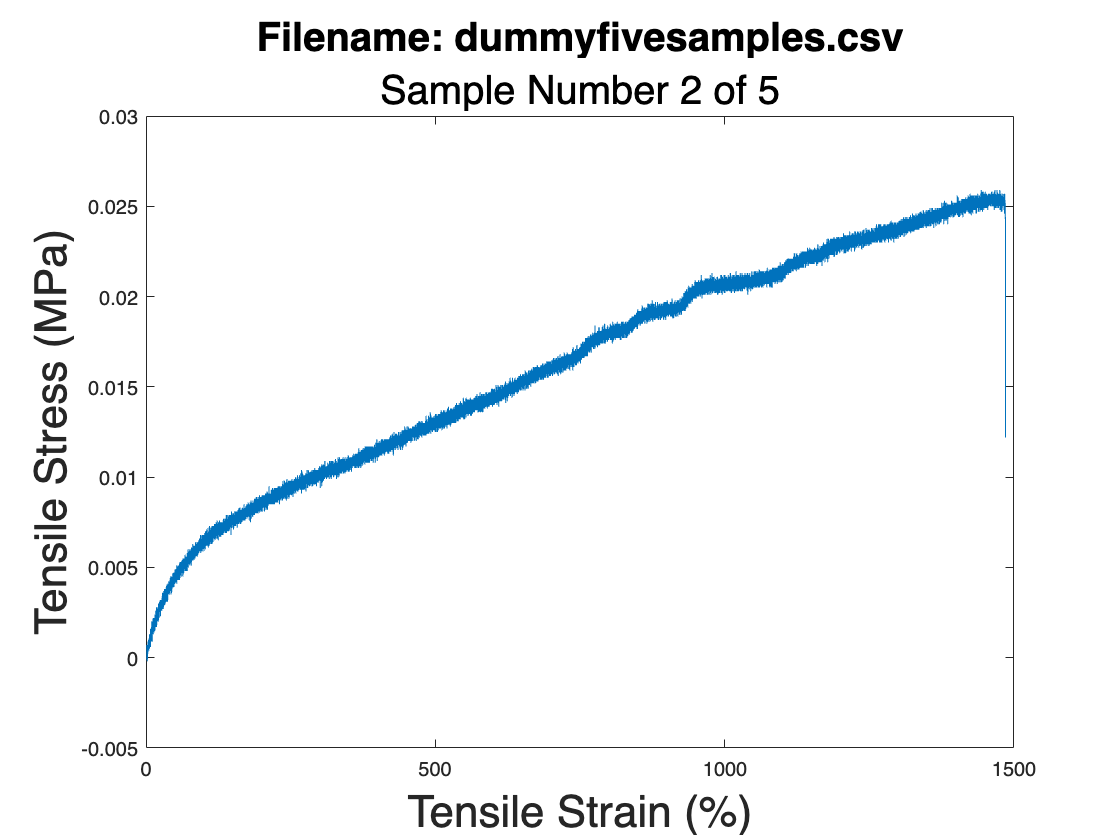

sample_number = 3

sample_number_check = 3

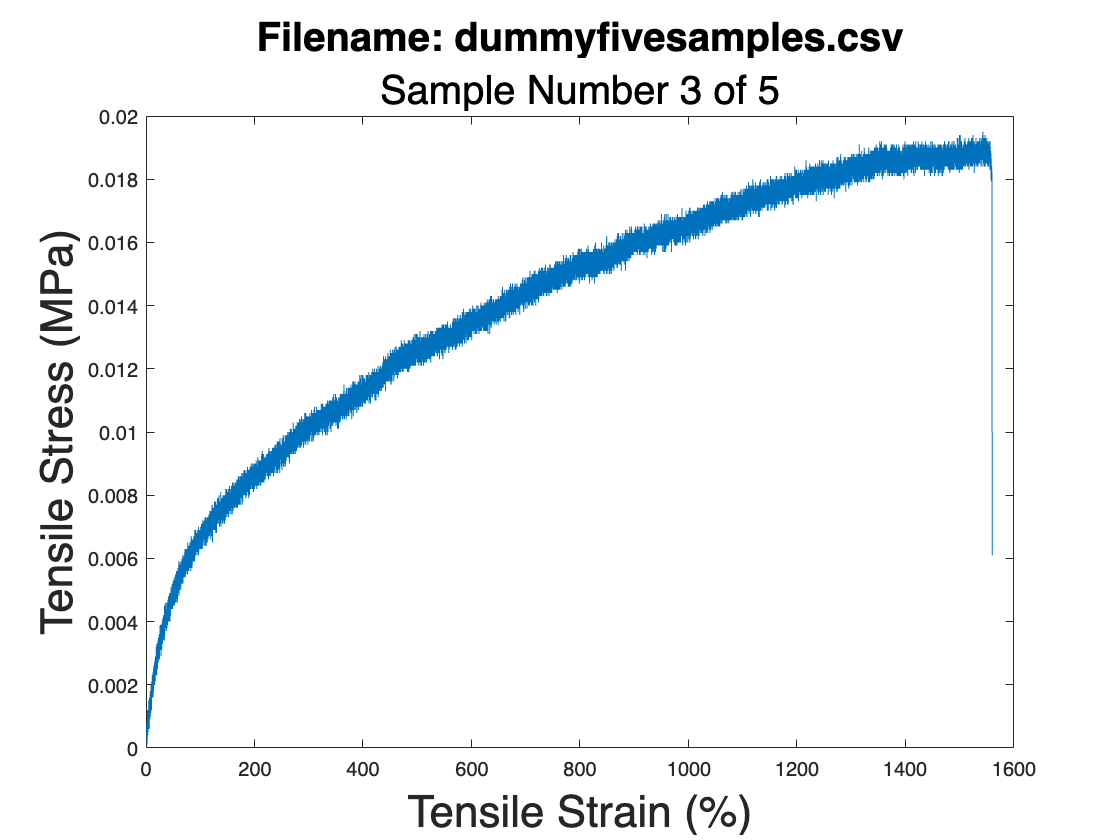

sample_number = 4

sample_number_check = 4

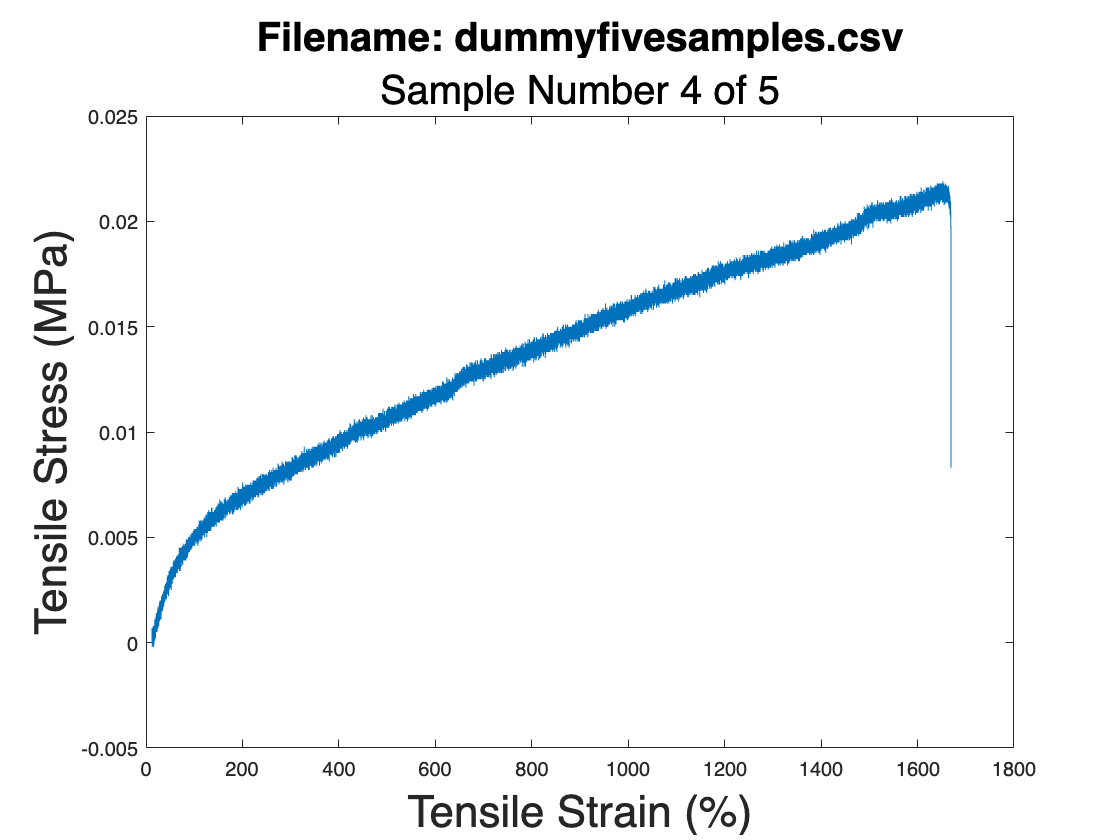

sample_number = 5

sample_number_check = 5

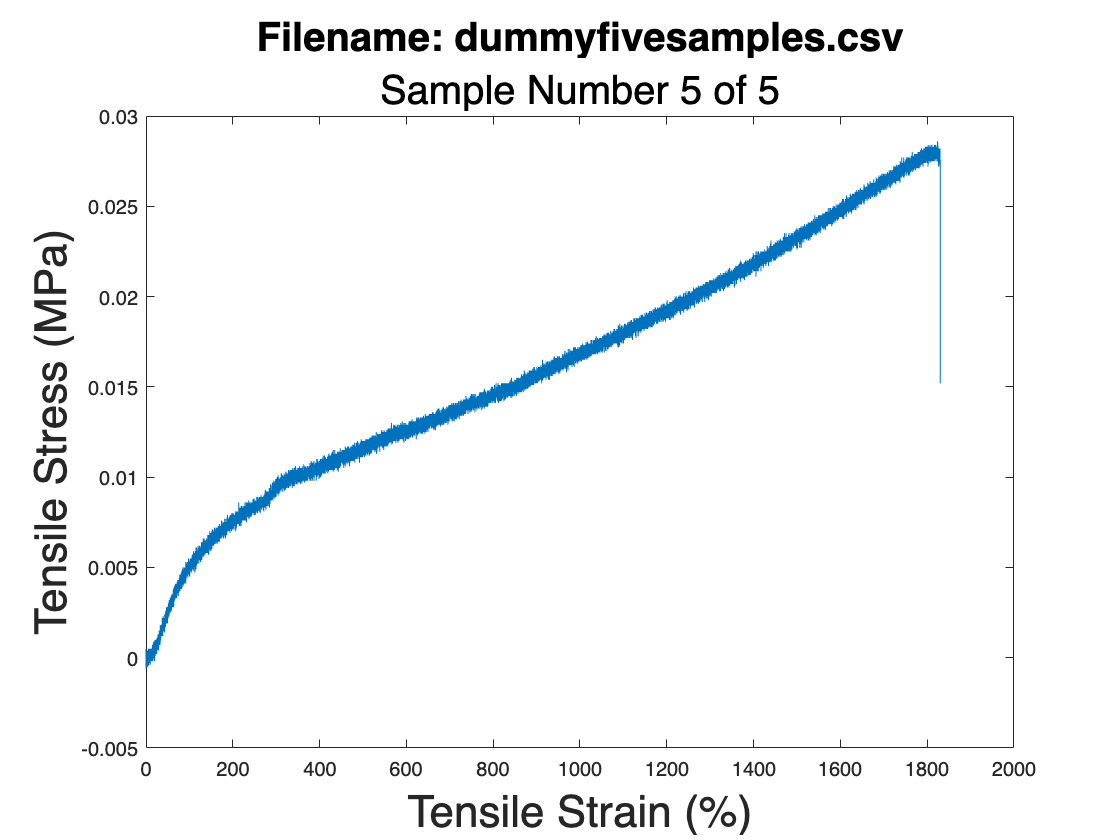

Filename: dummyonesample.csv

File 2 out of 2

num_samples_list = 1

indexes = 1

tensile_strain_index = 5

tensile_stress_index = 6

sample_number = 1

sample_number_check = 1

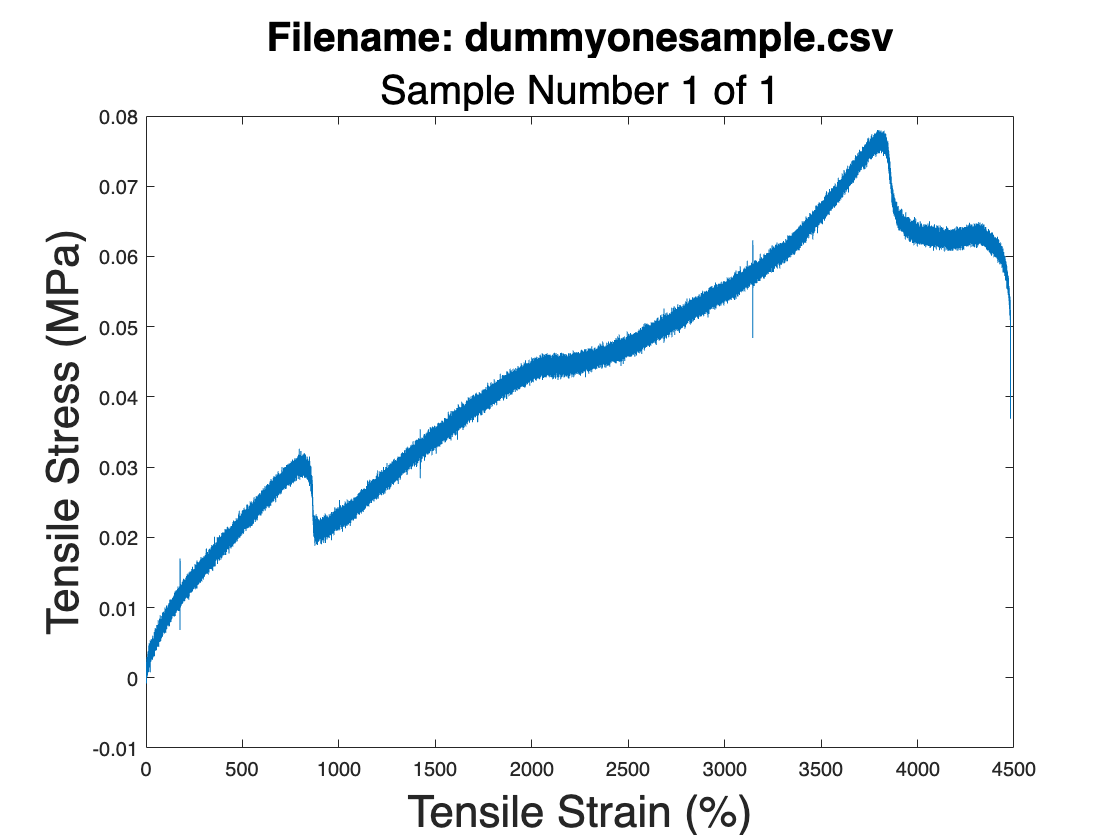

%Initialize matrices that will be used later: 
%Force_N = [];
%Displacement_mm = [];
%Tensile_stress_MPa = []; %in MPa 
%Tensile_strain = []; %in percentage (as opposed to mm) 

%Iterate through all the files: 
for n = 1:length(files)

file1 = csvfiles{n};

%NOTE: If it gives an error that says "Index exceeds the number of array
%elements(0), then that means the current folder is set to the wrong
%folder. Navigate to the correct new folder to fix the error. (Left Menu) 

%Report the filename and file number 
fprintf('Filename: %s',file1)
fprintf('File %d out of %d',n,length(files))
%(note: sprintf creates text/variables together as a string, while fprintf prints it) 

%import the data as both numbers (M) and values including text (C). 
Data_Numerical = readmatrix(file1); %extracts a matrix of data including numerical/decimal values 
Data_Values = readcell(file1); %extracts a matrix of data including text/headers 

num_samples_list = []; %initialize matrix in which to store the sample numbers 
indexes = []; %initialize matrix in which to store the indexes of where the data starts for each sample 
%Split up the data by counting the number of samples that were tested in
%the data 
for z = 1:length(Data_Numerical)
    if isnan(Data_Numerical(z,1)) == 0 %check whether an entry is a sample number, rather than NaN (no data in cell) 
        num_samples_list = [num_samples_list ; Data_Numerical(z,1)]; %store sample numbers in num_samples_list 
        indexes = [indexes ; z]; %store index numbers for start of data set for each sample 
    end
end

    %Report the tables obained from the above "for loop" 
    num_samples_list %print/report the samples list table 
    indexes %print / report the indexes table 

%Extract where (in which columns) the desired data is located, so that we
%can pull it out whenever we next need it 
for v = 1:width(Data_Numerical)
    if string(Data_Values(1,v))=="Tensile stress"
        tensile_stress_index = v 
    elseif string(Data_Values(1,v))=="Tensile strain (Displacement)"
        tensile_strain_index = v 
    end 
end


%%Extract the data itself for a given file: 
for m = 1:length(num_samples_list) %loops through each of the individual samples in a file 
    if not(m==length(num_samples_list)) %if we have not yet looped to the last sample 
        sample_number = m %extracts what we think the sample number is 
        sample_number_check = Data_Numerical(indexes(m)) %extracts actual sample number from instron data, to double check
        numerical_data = Data_Numerical(indexes(m):indexes(m+1)-1,:); %section out only the data for an individual sample, including the headers (NaN's) 
        %Below, we need to section out only the data (no headers / NaN's)
        %that include the stress and strain. 
        Tensile_stress_MPa = numerical_data(3:end,tensile_stress_index); %in MPa 
        Tensile_strain = numerical_data(3:end,tensile_strain_index); %in % 

        %Plot stress-strain data (note: if you change this, make sure to
        %change the other part of the code equivalent to it below, too) 
        figure
        plot(Tensile_strain,Tensile_stress_MPa); %plot data plot(x_data,y_data) 
        %ax = gca; %use gca for font size for chart 
        %ax.FontSize = 18; %set font for the title of the chart 
        main_title_content = sprintf('Filename: %s',csvfiles{n});
        sub_title_content = sprintf('Sample Number %d of %d',sample_number_check,length(num_samples_list));
        title(main_title_content,sub_title_content,'FontSize',20); 
        ylabel('Tensile Stress (MPa)','FontSize',22); %label y-axis
        xlabel('Tensile Strain (%)','FontSize',22);
        %ylim([-0.03,ylimitmax]) %1 is the max it should be 
        hold on;

    elseif m==length(num_samples_list) %if we have looped to the last sample 
        %We need a separate chunk of code here because the indexes(m+1)-1
        %does not work, and we need to use "end" instead (extract data up
        %until the end of the sample dataset, rather than up until the next
        %subsequent sample dataset). 
        sample_number = m %extracts what we think the sample number is 
        sample_number_check = Data_Numerical(indexes(m)) %extracts actual sample number from instron data, to double check 
        numerical_data = Data_Numerical(indexes(m):end,:); %section out only the data for an individual sample, including the headers (NaN's) 
        %Below, we need to section out only the data (no headers / NaN's)
        %that include the stress and strain. 
        Tensile_stress_MPa = numerical_data(3:end,tensile_stress_index); %in MPa 
        Tensile_strain = numerical_data(3:end,tensile_strain_index); %in % 

        %Plot stress-strain data for the last sample  
        figure
        plot(Tensile_strain,Tensile_stress_MPa); %plot data plot(x_data,y_data) 
        %ax = gca; %use gca for font size for chart 
        %ax.FontSize = 18; %set font for the title of the chart 
        main_title_content = sprintf('Filename: %s',csvfiles{n});
        sub_title_content = sprintf('Sample Number %d of %d',sample_number_check,length(num_samples_list));
        title(main_title_content,sub_title_content,'FontSize',20); 
        ylabel('Tensile Stress (MPa)','FontSize',22); %label y-axis
        xlabel('Tensile Strain (%)','FontSize',22);
        %ylim([-0.03,ylimitmax]) %1 is the max it should be 
        hold on;

    end %end the "if" loop which helps extract the data properly depending on whether it's the last sample or within the first few samples 

end %stop looping through each individual sample in a file 

%old code... 
%Tensile_stress_MPa = numerical_data(:,5); %in MPa 
%Tensile_strain = numerical_data(:,4);


%%Plot Graphs 

%%Old graph plotting code... 
% %Plot stress-strain data  
% figure
% plot(Tensile_strain,Tensile_stress_MPa); %plot data plot(x_data,y_data) 
% %ax = gca; %use gca for font size for chart 
% %ax.FontSize = 18; %set font for the title fo the chart 
% ylabel('Tensile Stress (MPa)','FontSize',22); %label y-axis
% xlabel('Tensile Strain (%)','FontSize',22)
% %ylim([-0.03,ylimitmax]) %1 is the max it should be 
% hold on; 




end %end the loop of interation between the different files 



%extract measurement parameters from text headers of csv file: 
%N/A, since right now we just have the table headers and nothing else... 

%Store numerical data into the following variables. 
%Note that the numbers 2,3,4,5 are the column numbers; they might change if
%data is exported differently from the Instron. So always make sure to use
%the same Instron method file & report file to ensure it exports just like
%this. 


## Code to Analyze Data For All Datasets 

Filename: dummyfivesamples.csv

File 1 out of 2

area_under_curve = 6.9968

area_under_curve2 = 1.2204

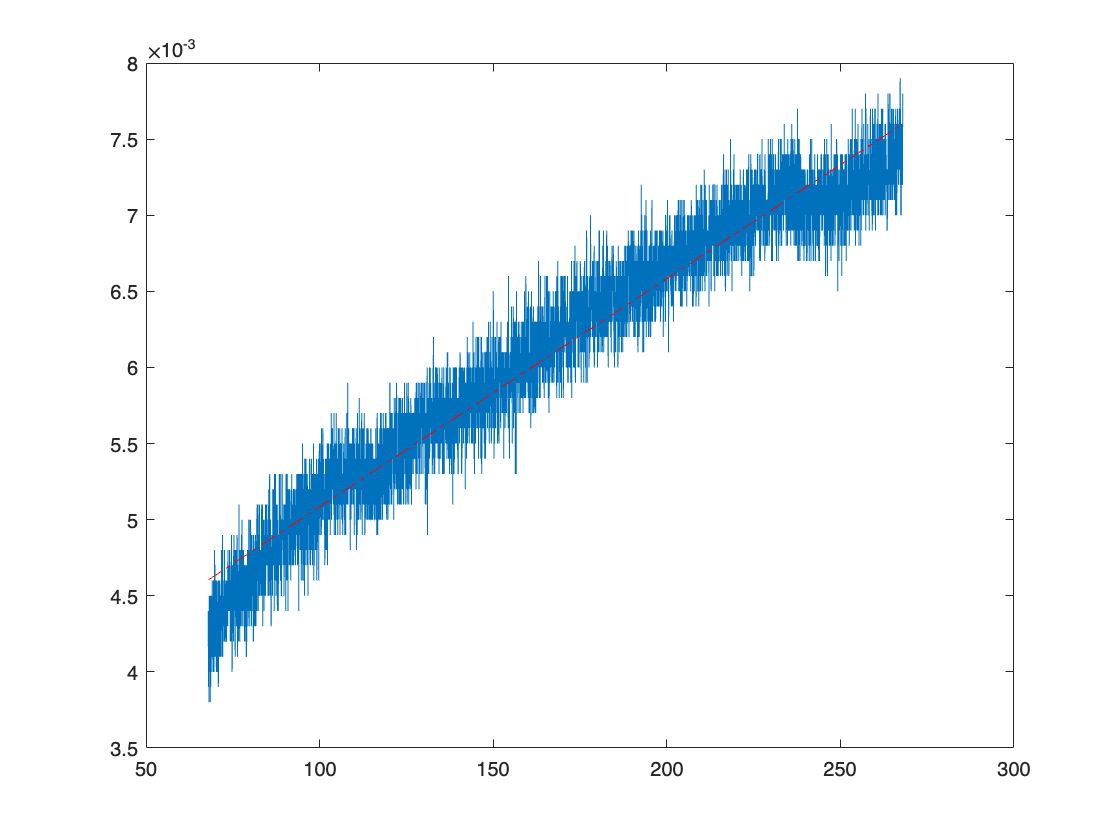

maximum_stress = 0.0124

point_at_which_data_is_dropping = 24749

stress_at_drop = 0.0105

strain_at_drop = 826.2393

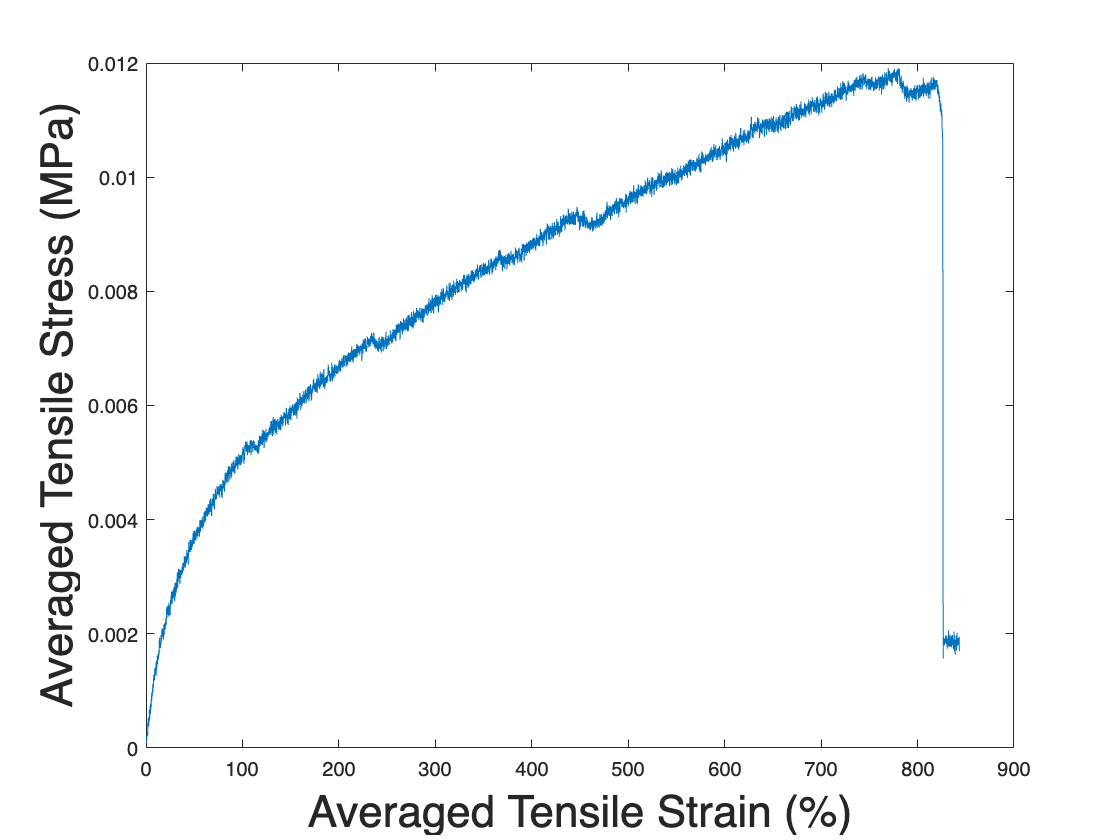

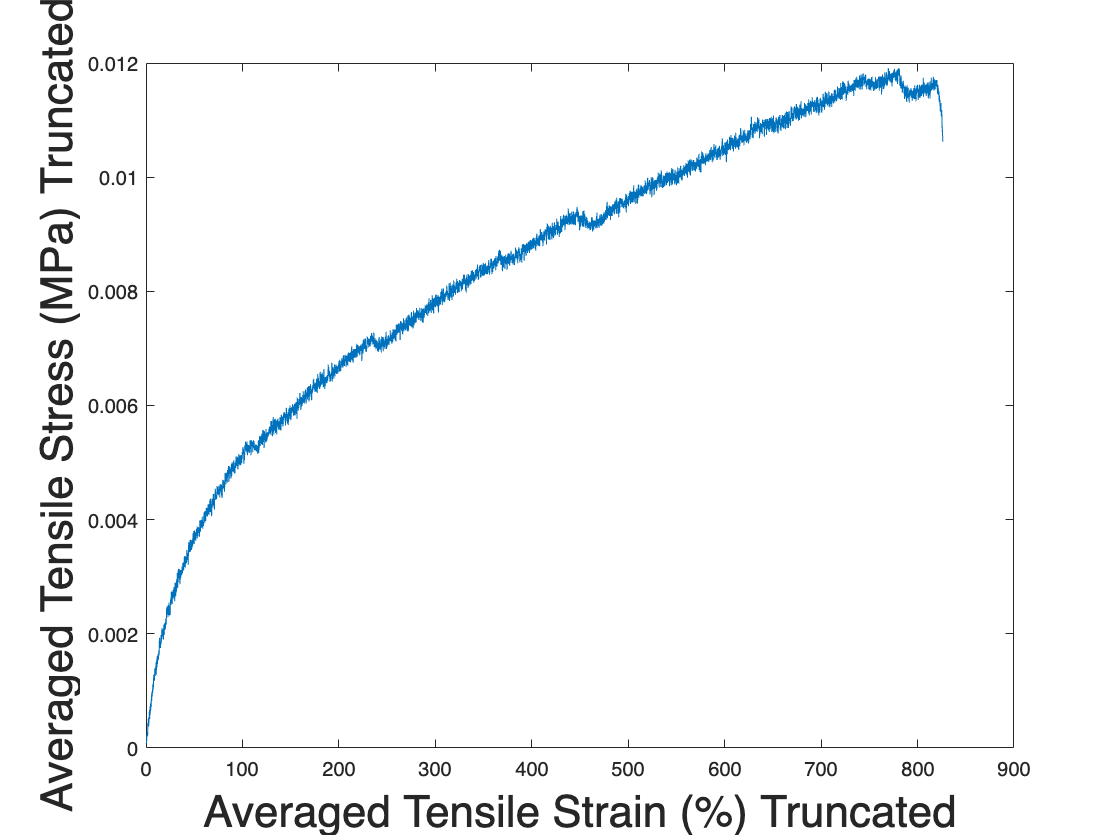

area_under_curve = 6.9623

ans = 24749

index_first_10_percent = 2474

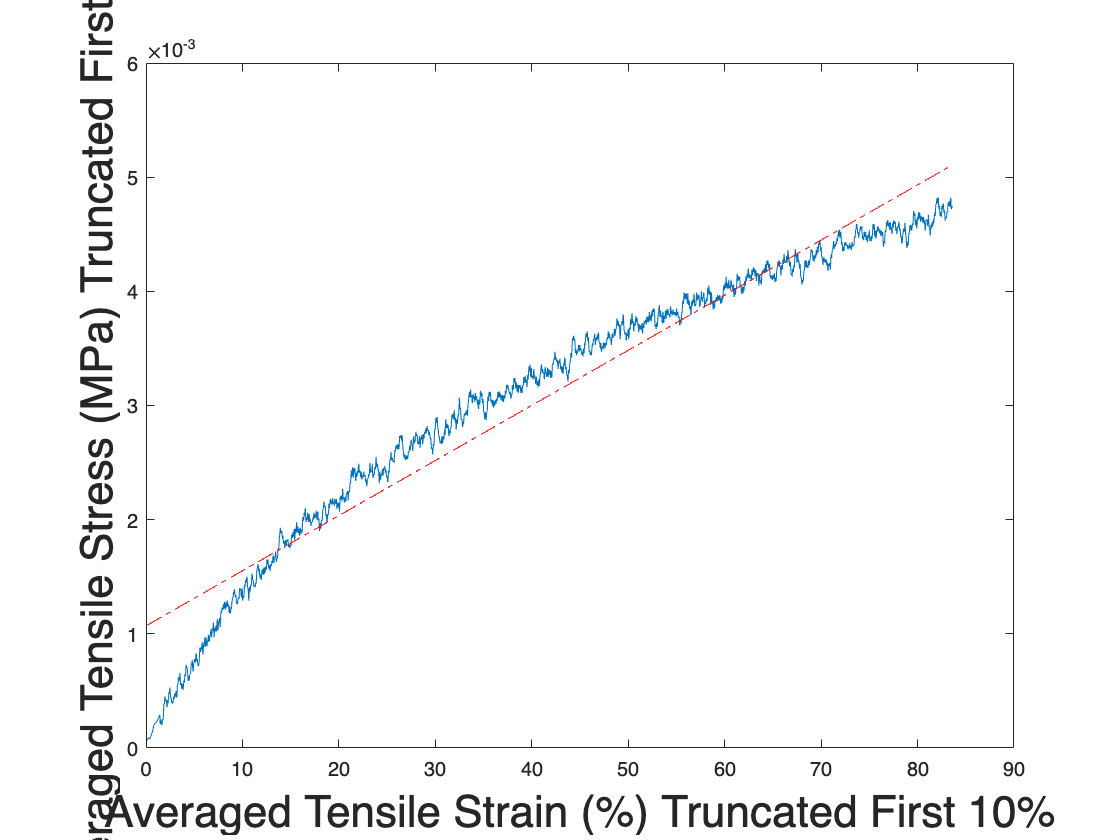

ylimitmax = 0.0119

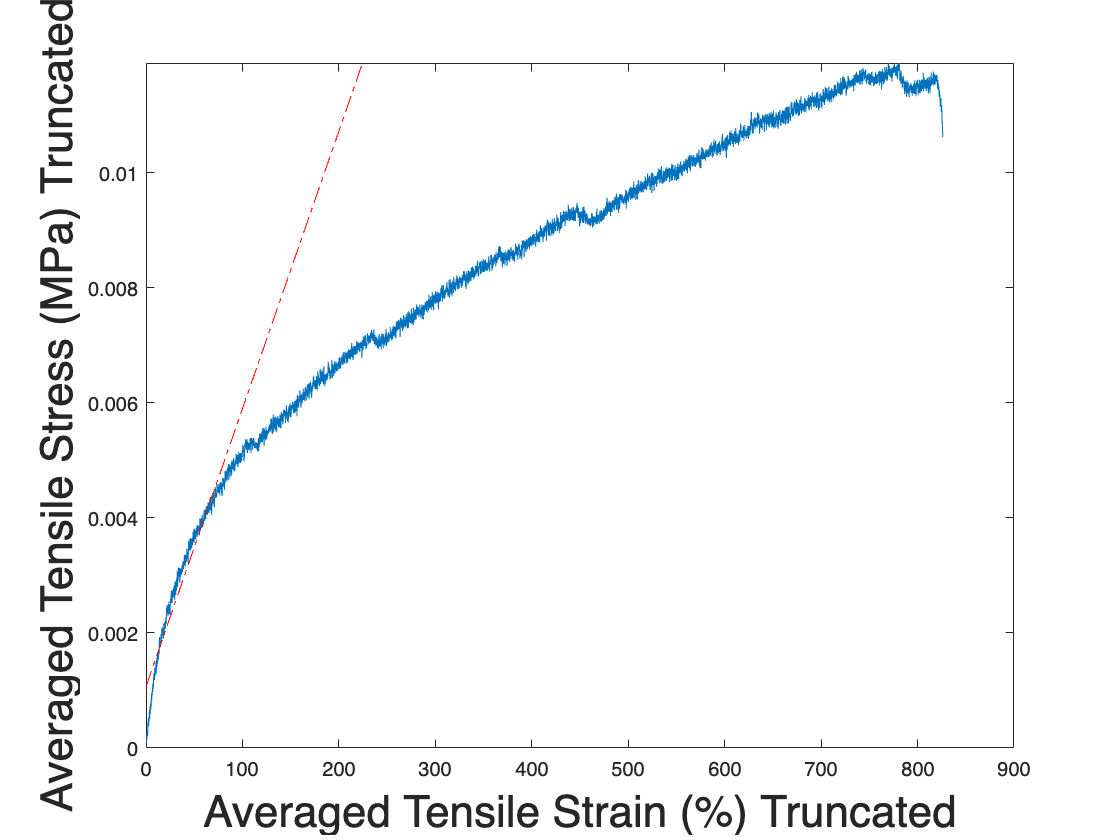

modulus = 4.8281e-05

fracture_energy = 6.9623

ultimate_stress = 0.0119

ultimate_strain = 780.4895

area_under_curve = 24.0984

area_under_curve2 = 1.5632

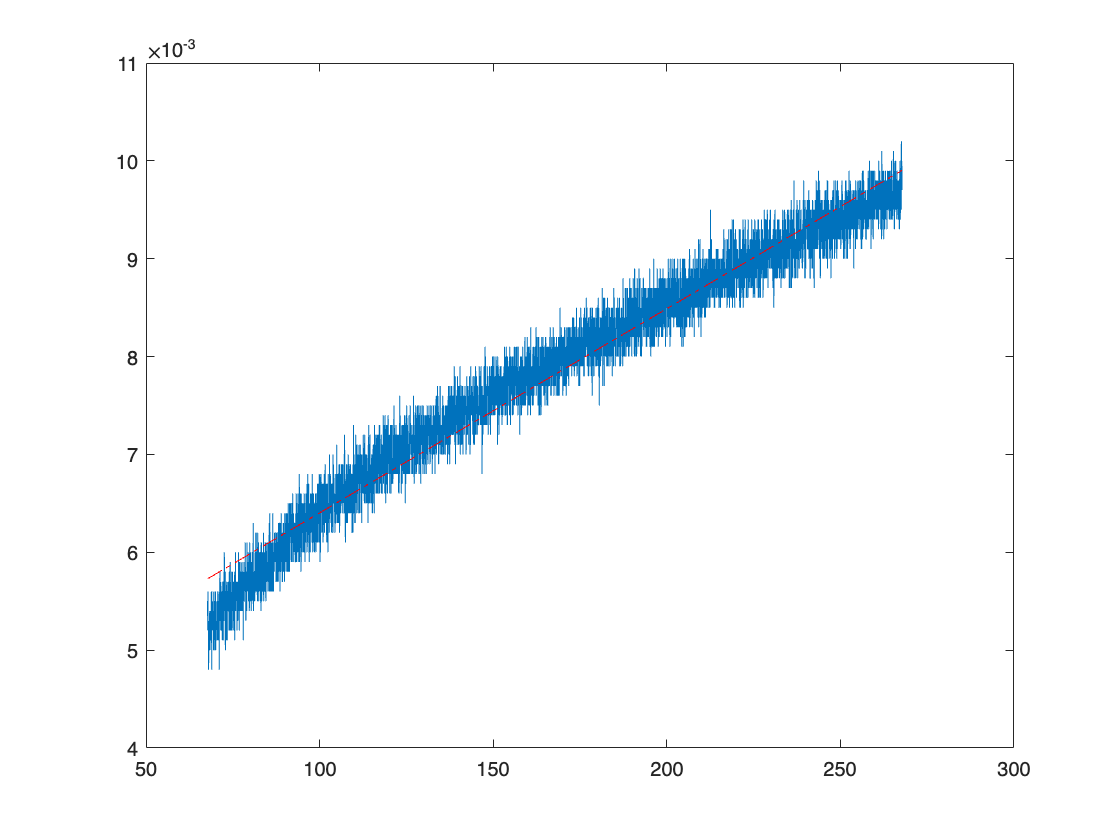

maximum_stress = 0.0259

Tensile_strain_truncated = 1.0e+03 *

    0.0011
    0.0011
    0.0012
    0.0012
    0.0012
    0.0012
    0.0013
    0.0013
    0.0014
    0.0014


Tensile_stress_MPa_truncated =     0.0007
         0
         0
    0.0002
    0.0007
    0.0004
    0.0002
    0.0001
         0
   -0.0001


Code was unable to truncated data at dropping point. So, all the data was used

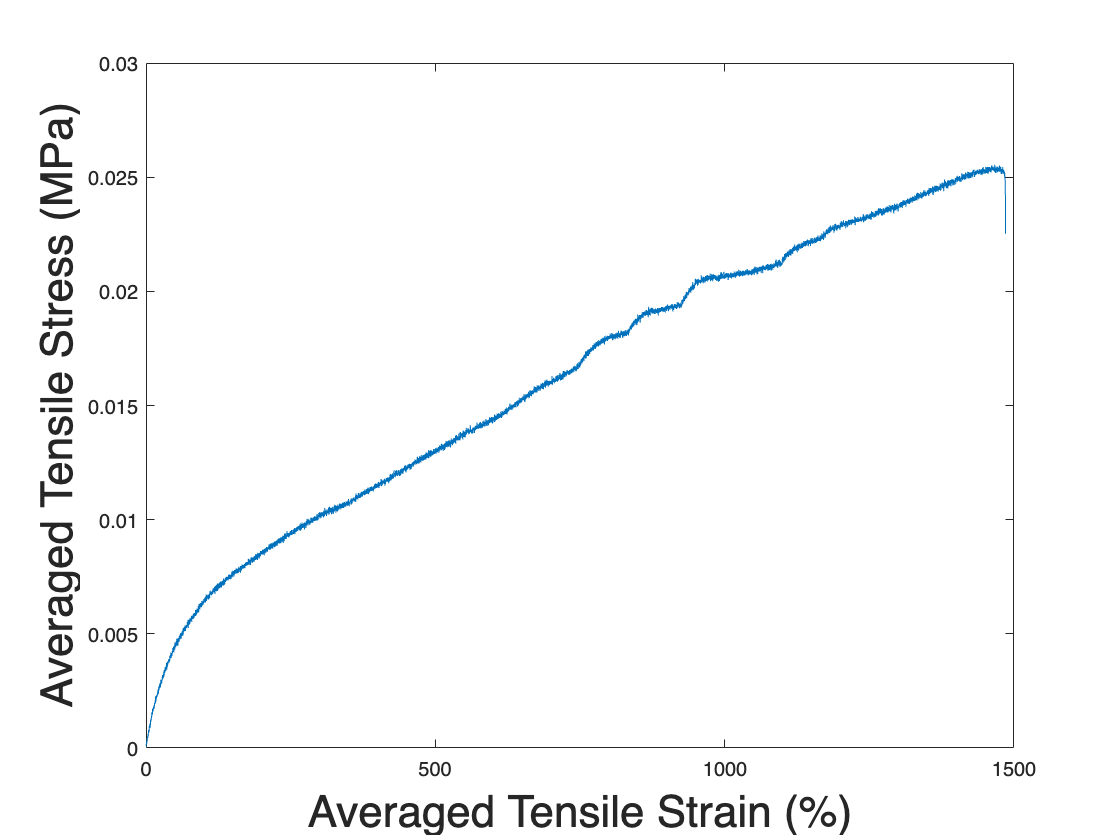

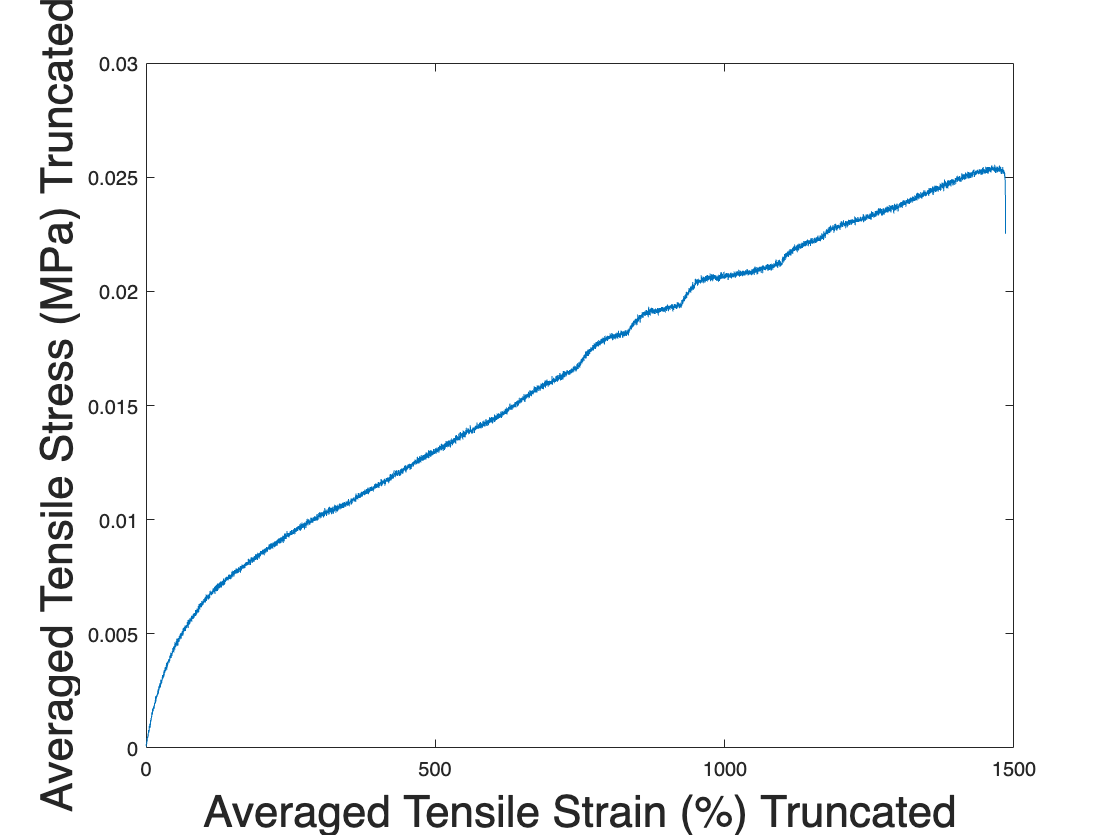

area_under_curve = 24.0956

ans = 44532

index_first_10_percent = 4453

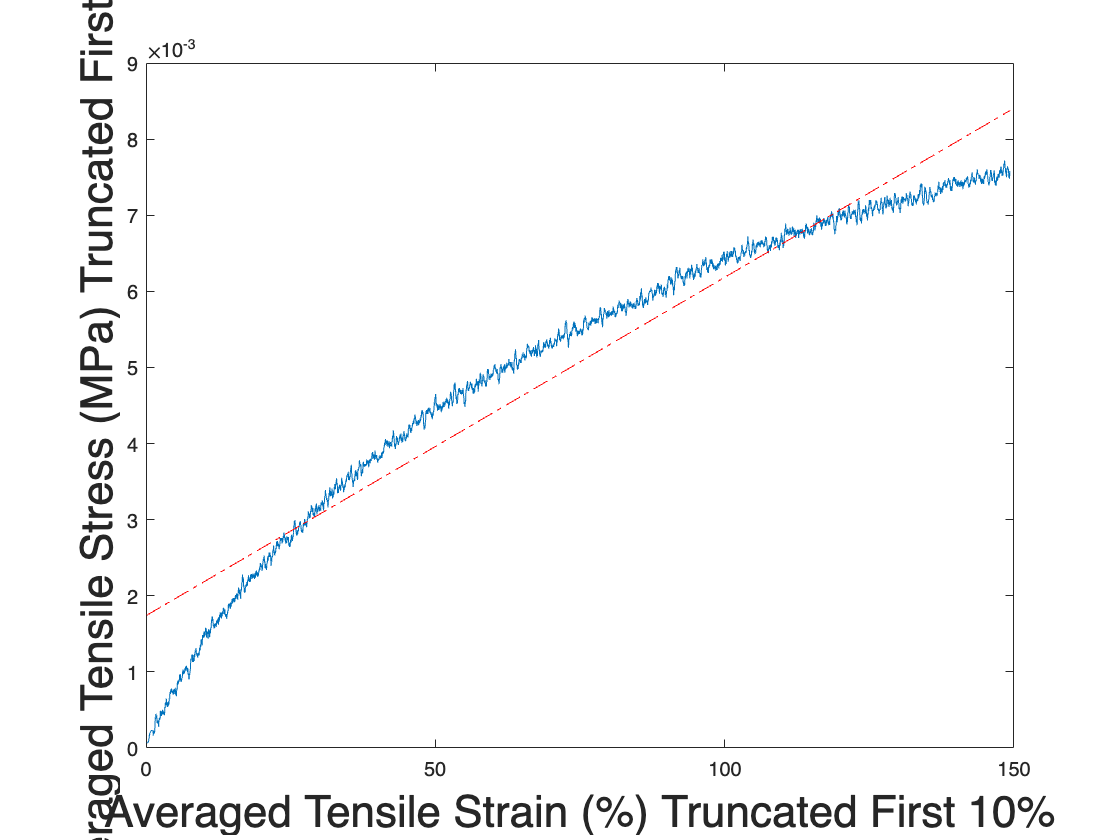

ylimitmax = 0.0255

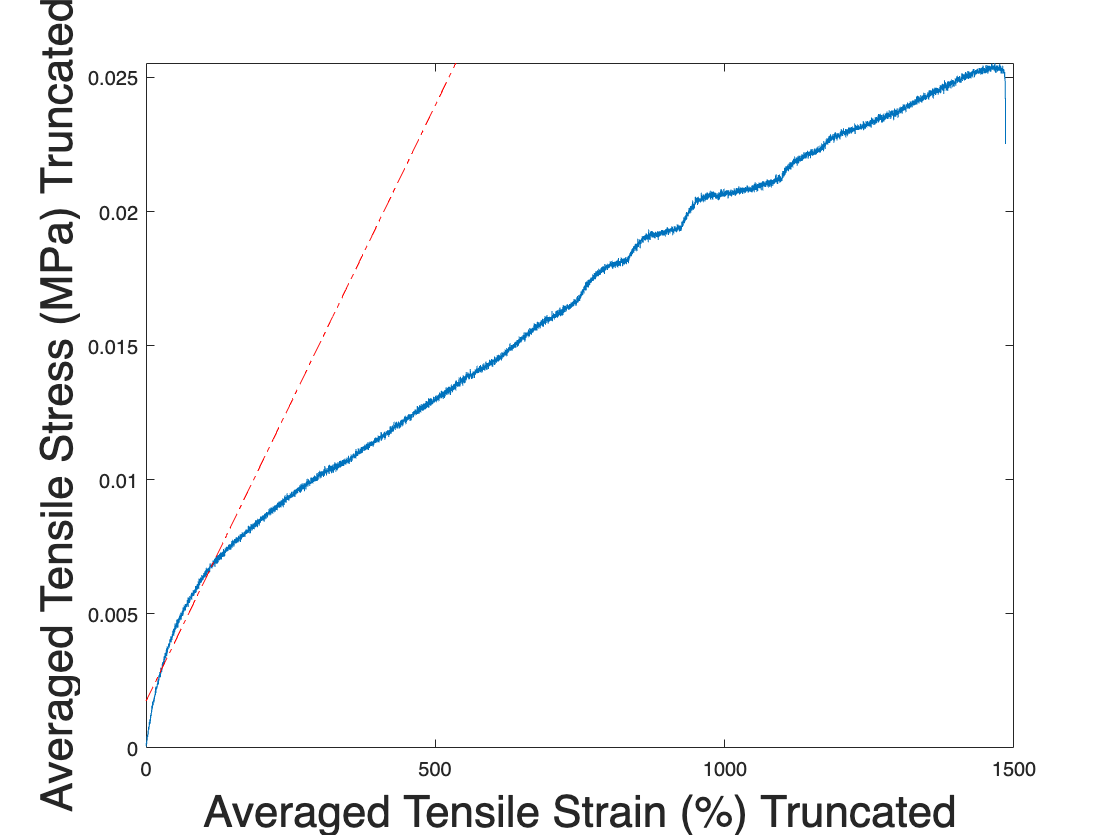

modulus = 4.4454e-05

fracture_energy = 24.0956

ultimate_stress = 0.0255

ultimate_strain = 1.4668e+03

area_under_curve = 21.8615

area_under_curve2 = 1.5858

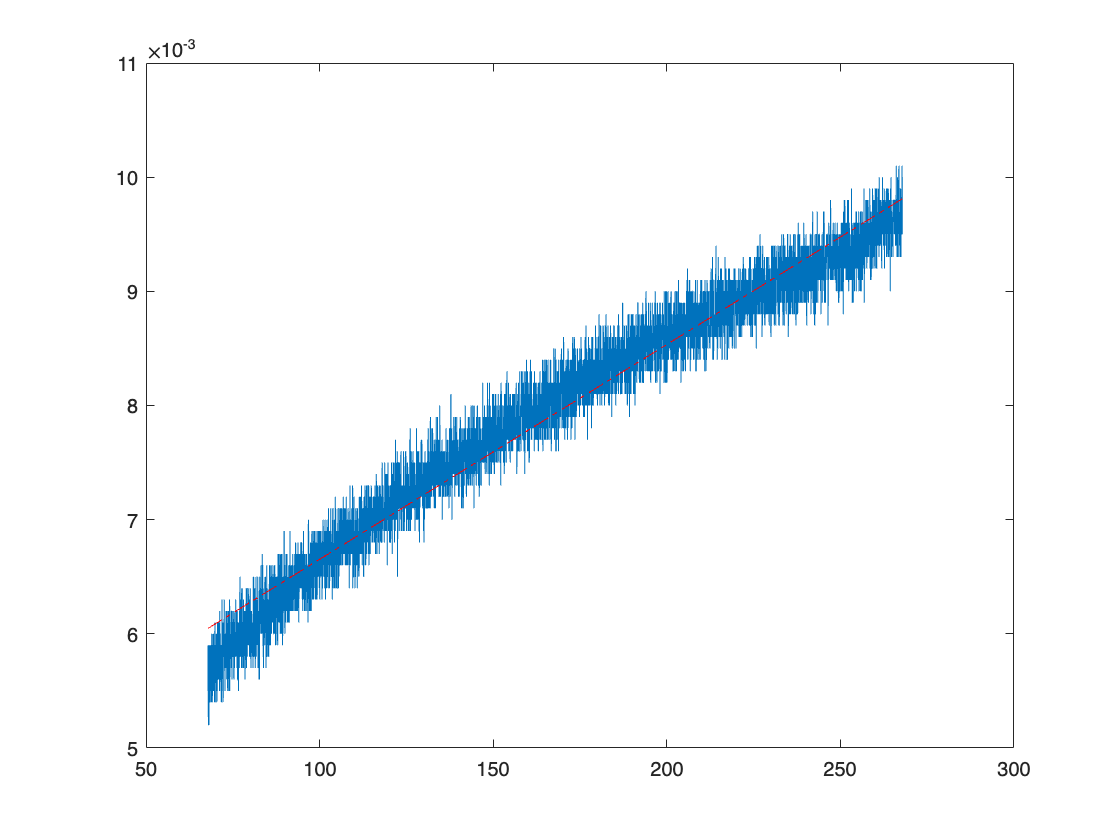

maximum_stress = 0.0195

point_at_which_data_is_dropping = 46754

stress_at_drop = 0.0177

strain_at_drop = 1.5596e+03

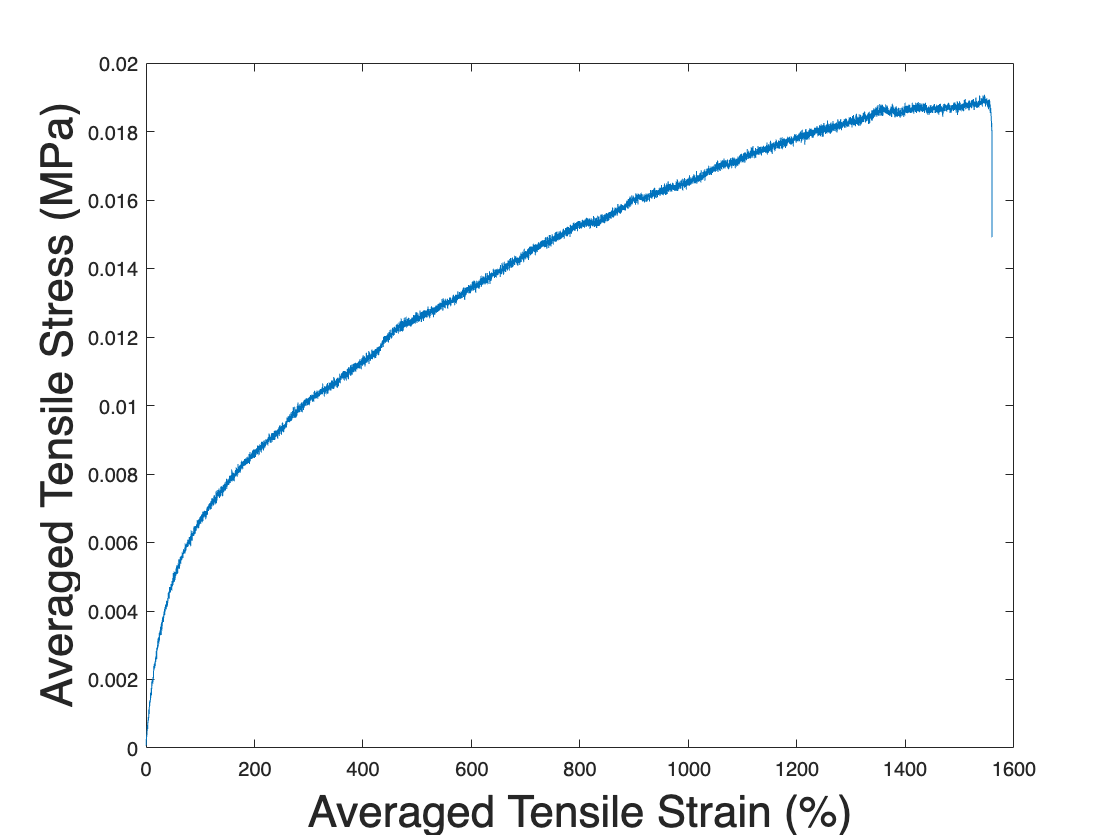

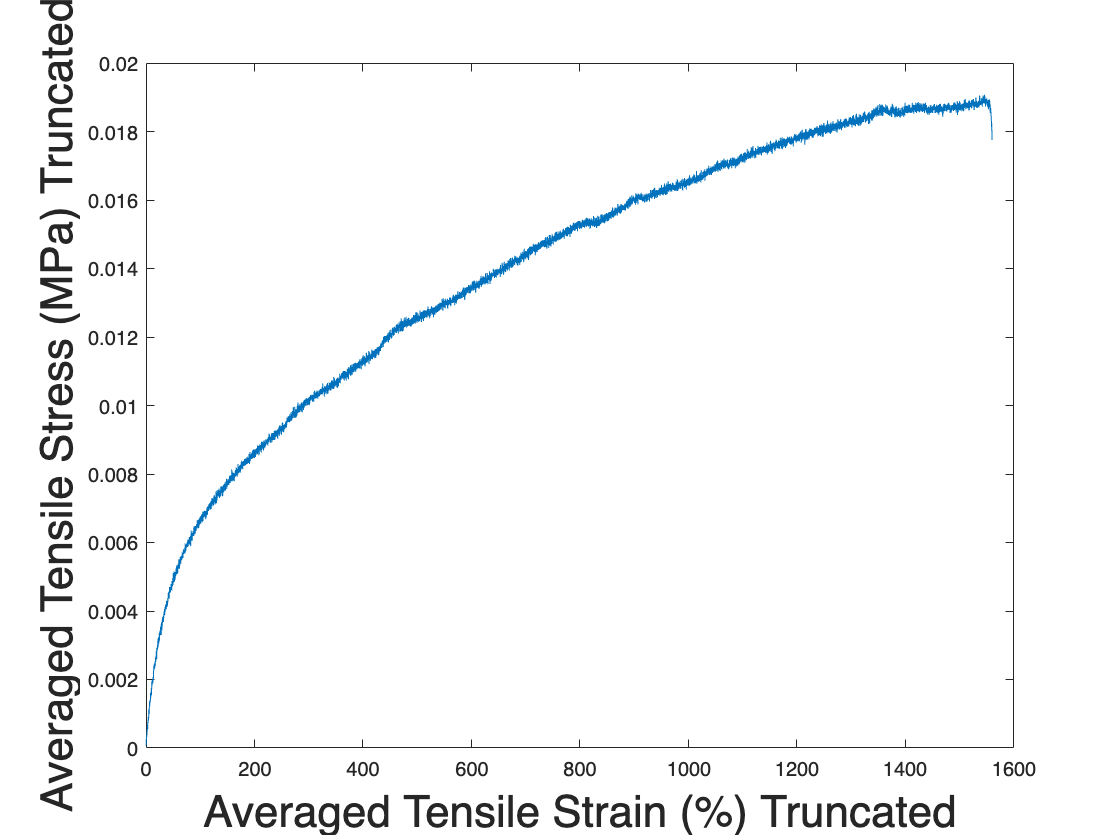

area_under_curve = 21.8565

ans = 46754

index_first_10_percent = 4675

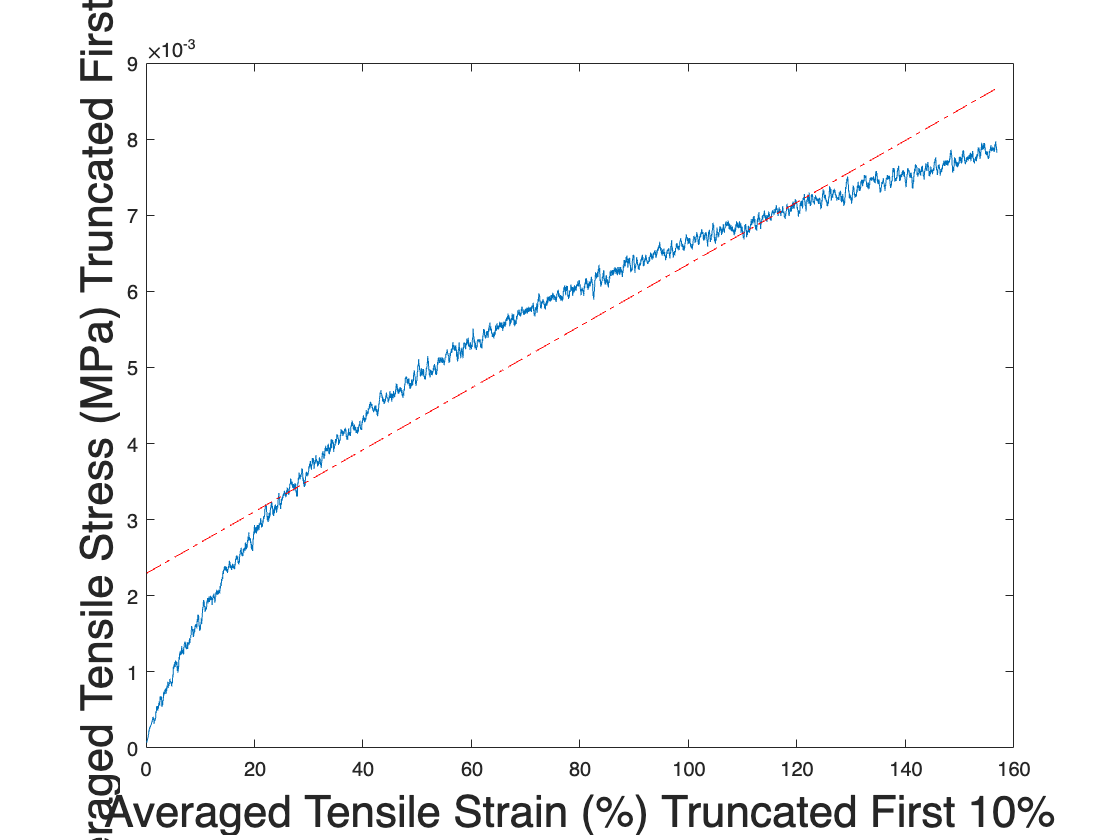

ylimitmax = 0.0191

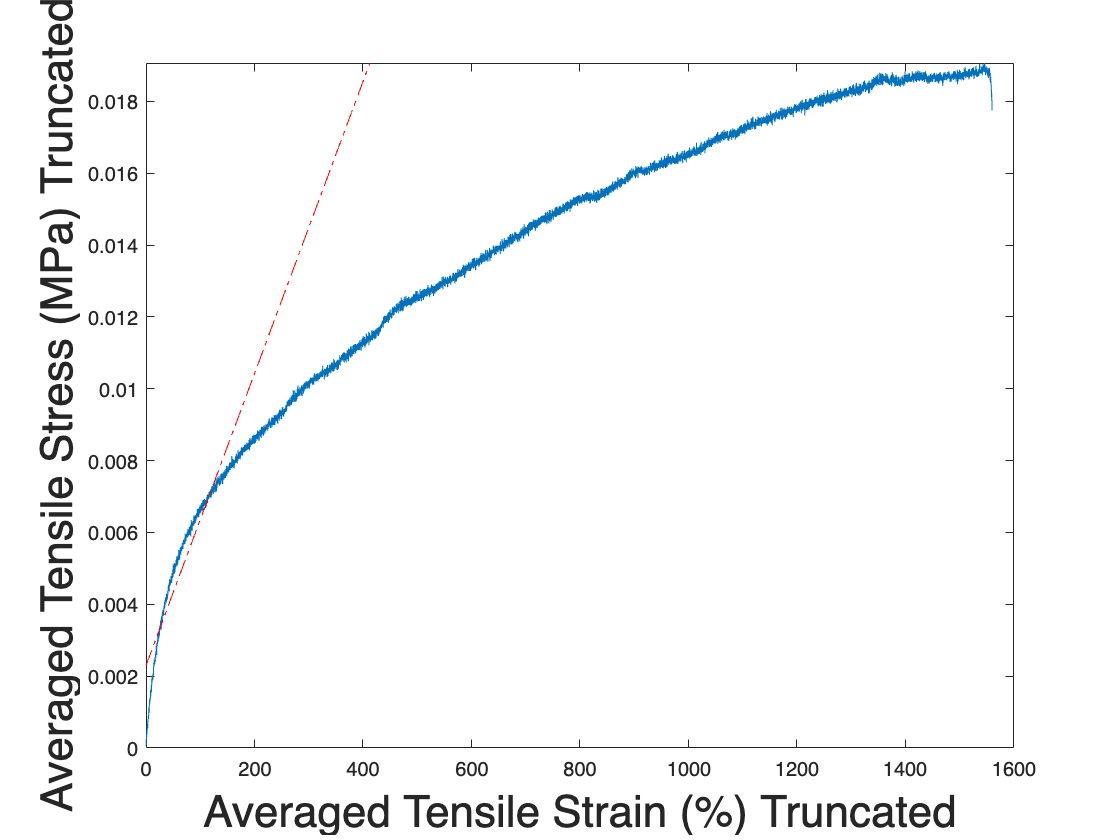

modulus = 4.0653e-05

fracture_energy = 21.8565

ultimate_stress = 0.0191

ultimate_strain = 1.5457e+03

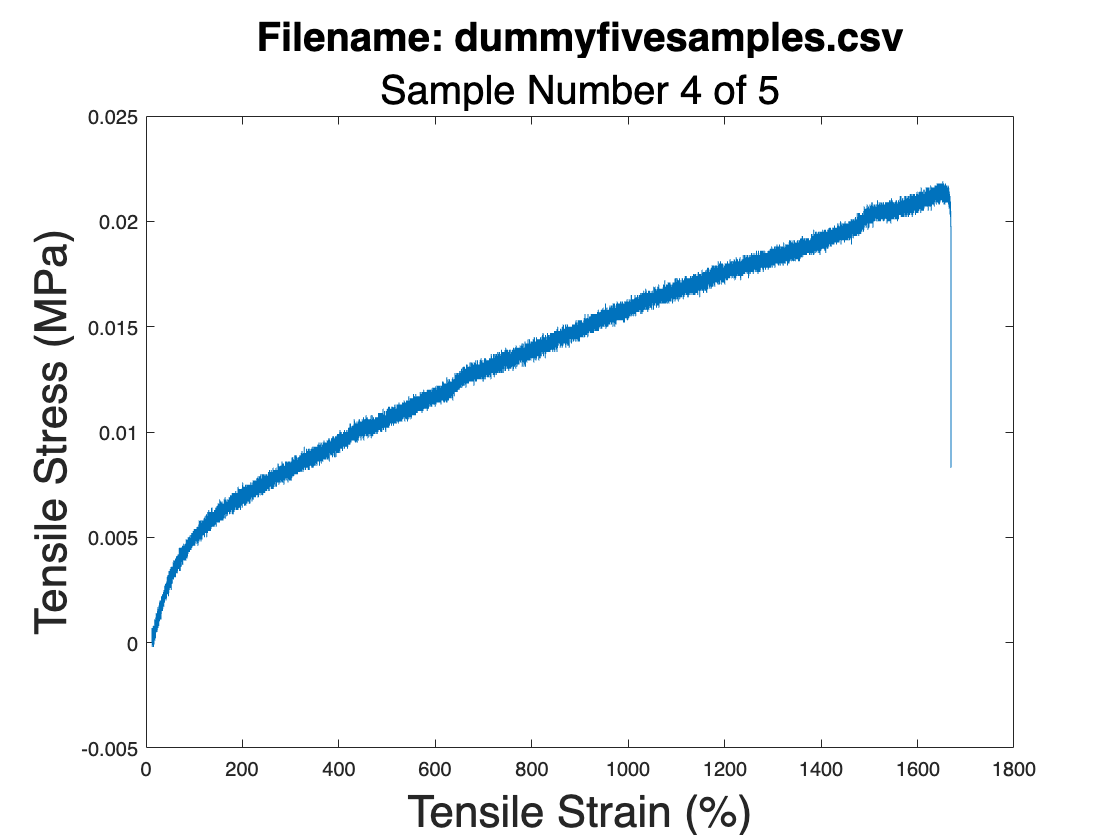

area_under_curve = 22.6818

area_under_curve2 = 1.2937

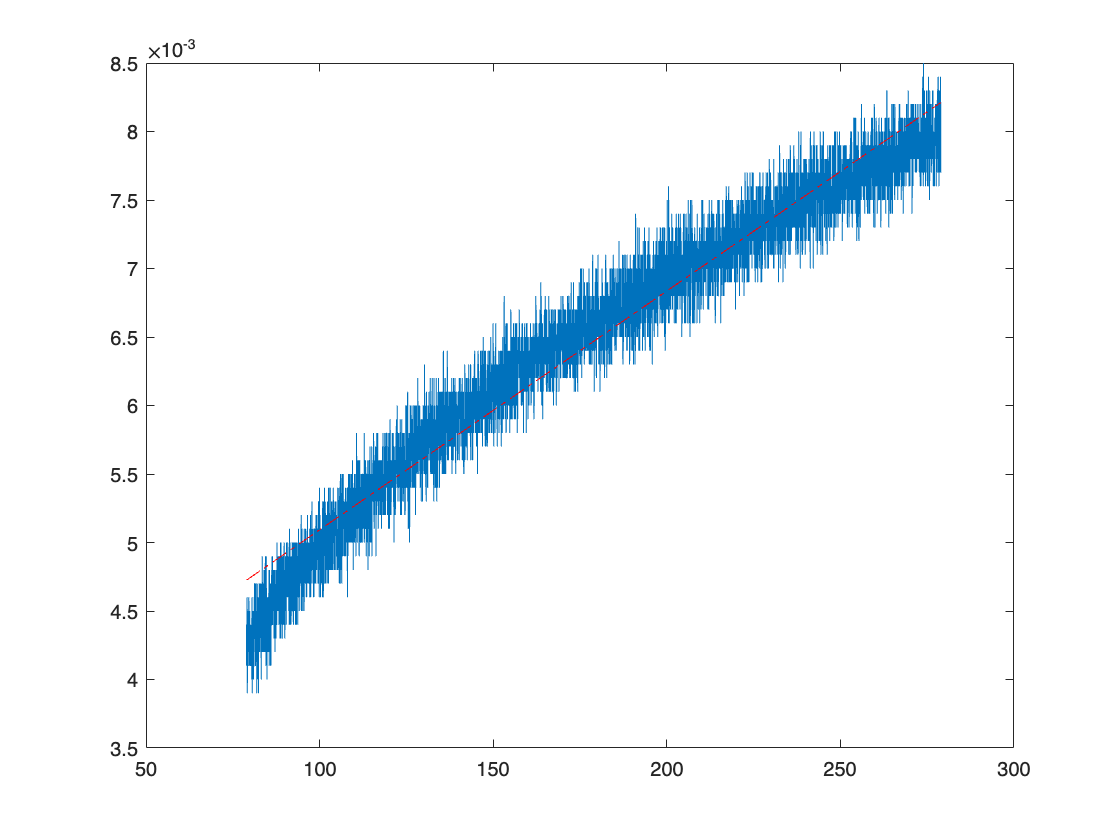

maximum_stress = 0.0219

Tensile_strain_truncated = 1.0e+03 *

    0.0123
    0.0123
    0.0123
    0.0123
    0.0124
    0.0124
    0.0125
    0.0125
    0.0125
    0.0126


Tensile_stress_MPa_truncated =     0.0007
    0.0002
         0
    0.0005
    0.0006
    0.0001
         0
    0.0003
    0.0002
   -0.0001


Code was unable to truncated data at dropping point. So, all the data was used

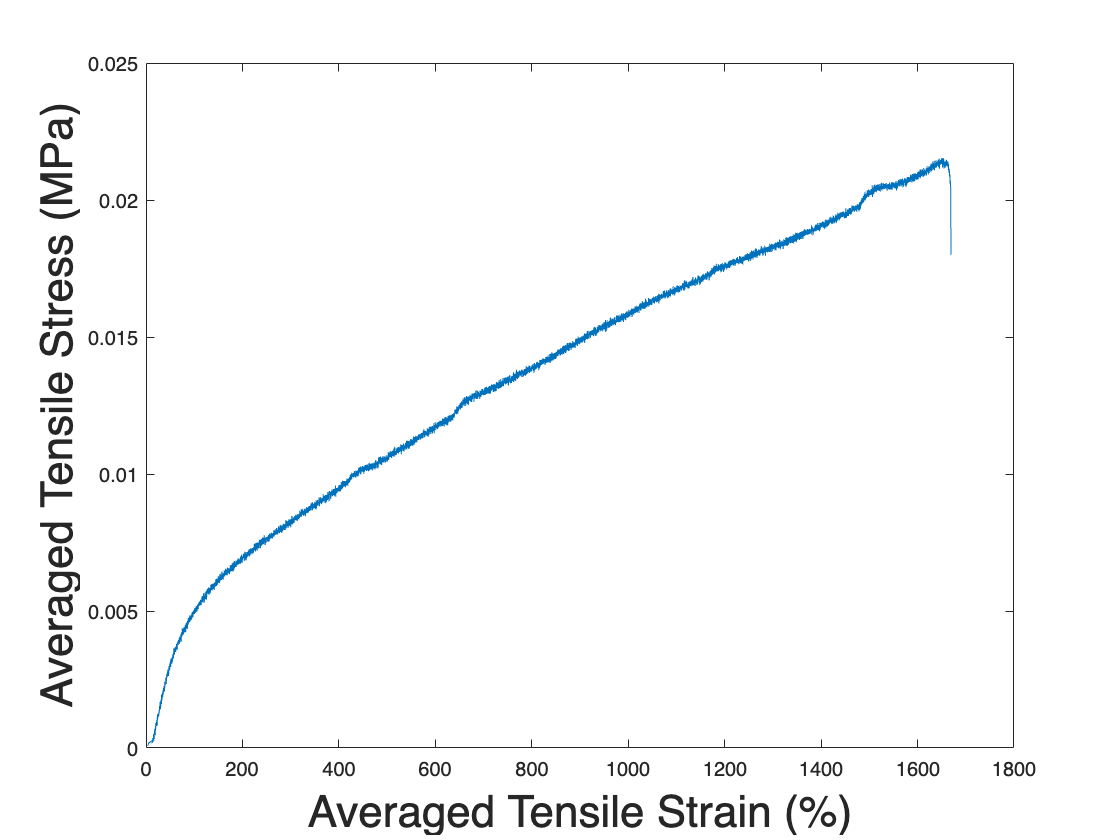

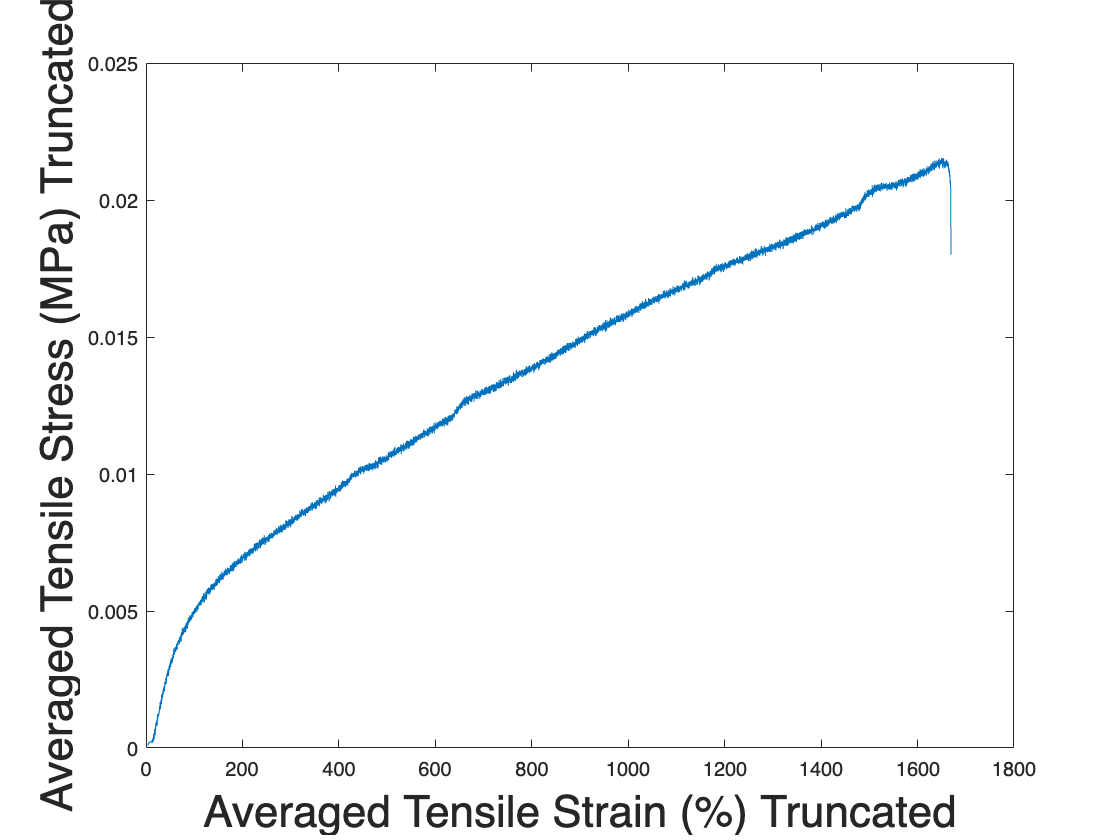

area_under_curve = 22.6813

ans = 49715

index_first_10_percent = 4971

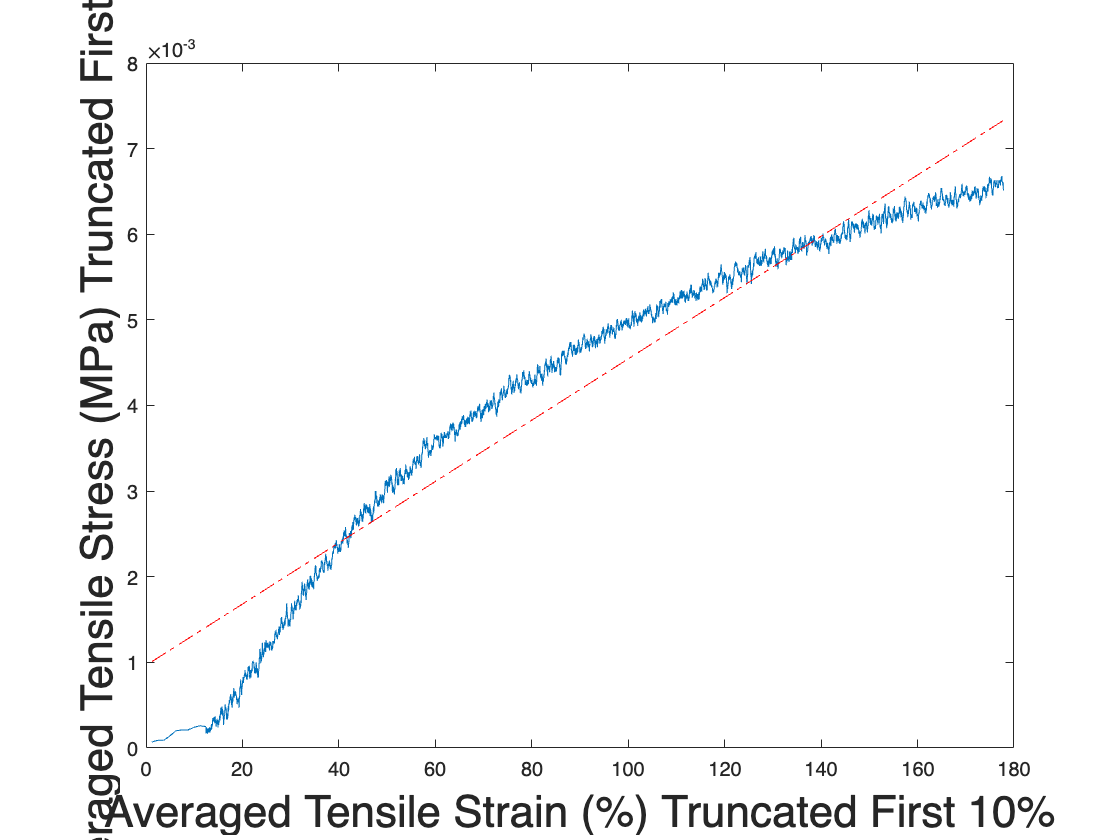

ylimitmax = 0.0215

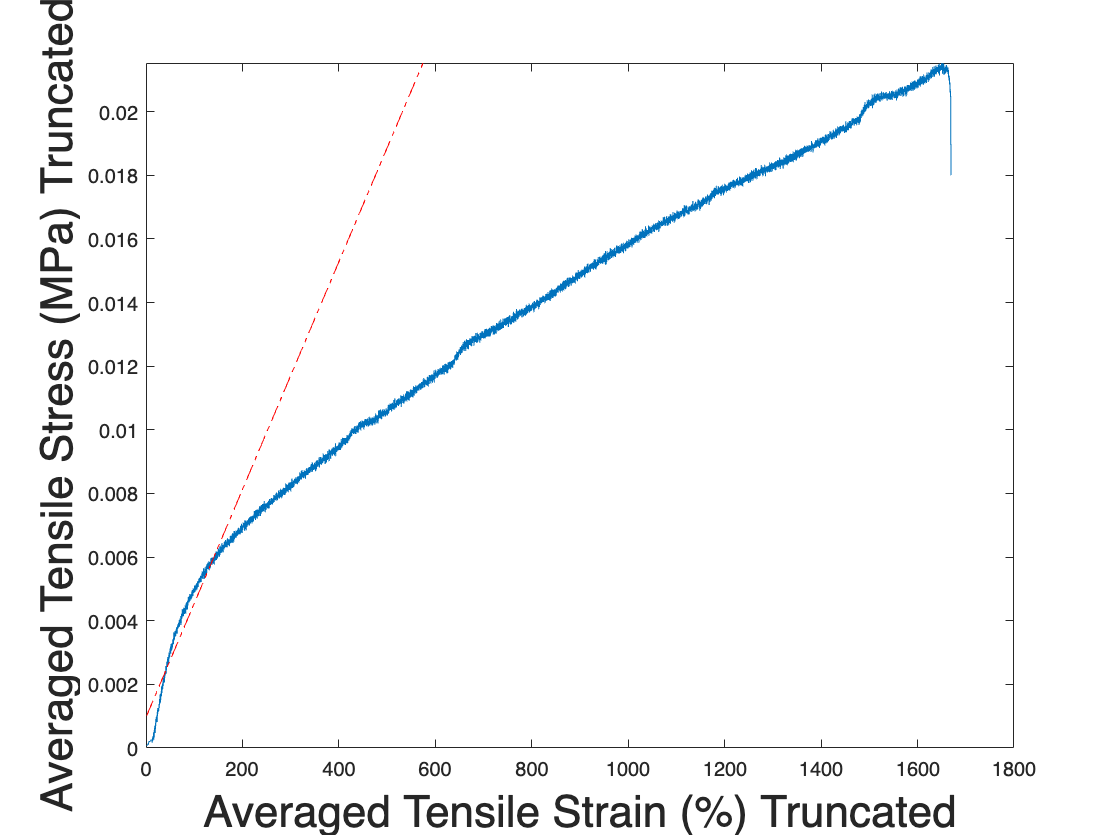

modulus = 3.5793e-05

fracture_energy = 22.6813

ultimate_stress = 0.0215

ultimate_strain = 1.6500e+03

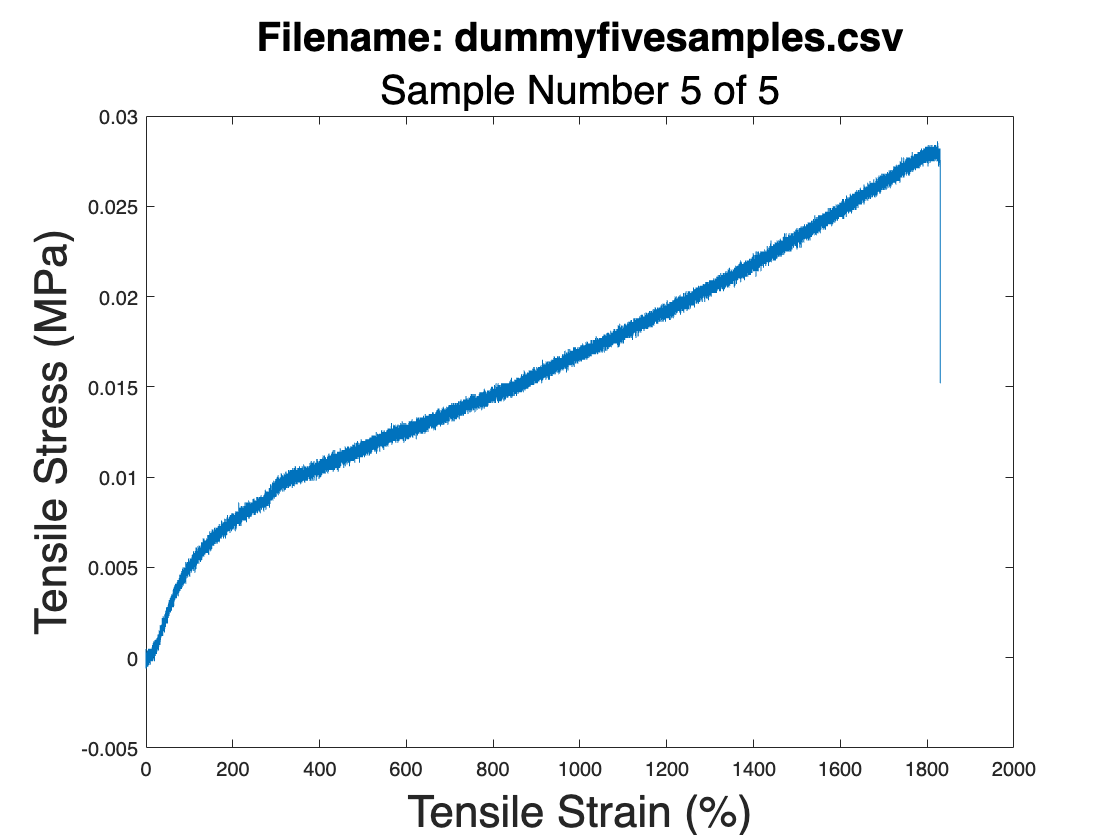

area_under_curve = 29.3272

area_under_curve2 = 1.3231

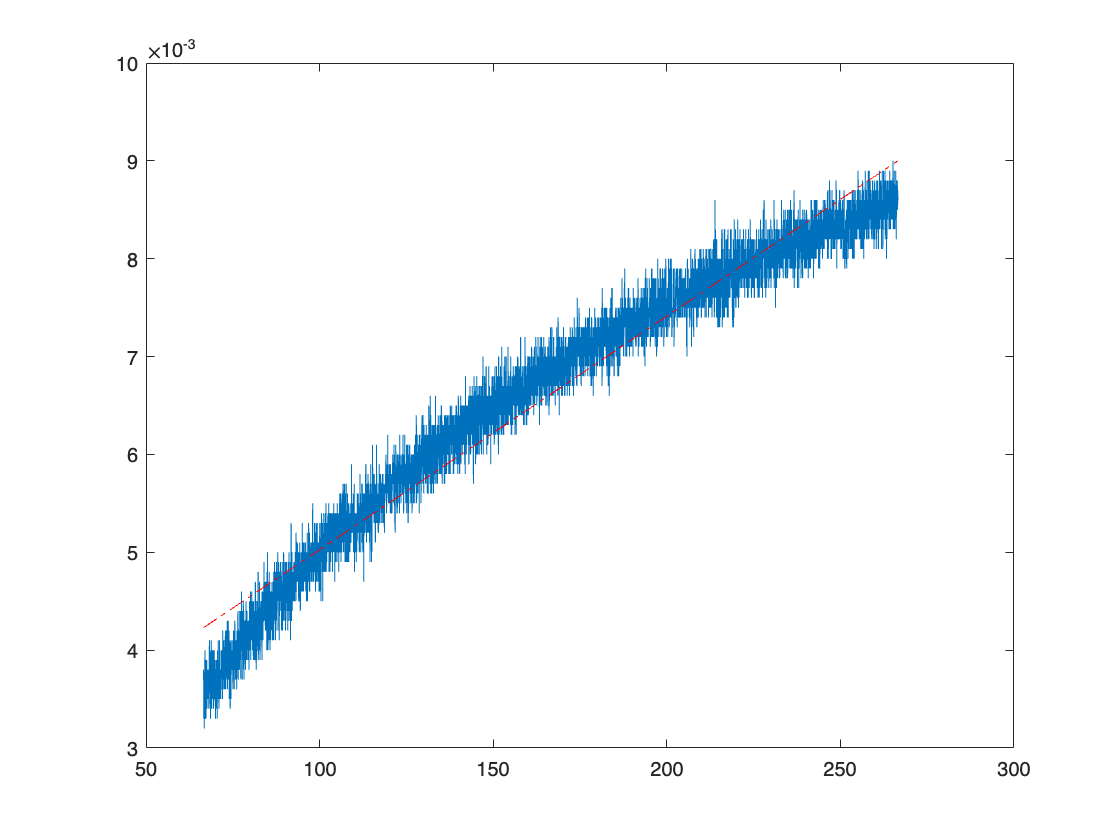

maximum_stress = 0.0286

Tensile_strain_truncated = 1.0e+03 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0002


Tensile_stress_MPa_truncated =    -0.0003
   -0.0003
    0.0001
         0
   -0.0003
    0.0005
    0.0005
   -0.0004
   -0.0002
   -0.0003


Code was unable to truncated data at dropping point. So, all the data was used

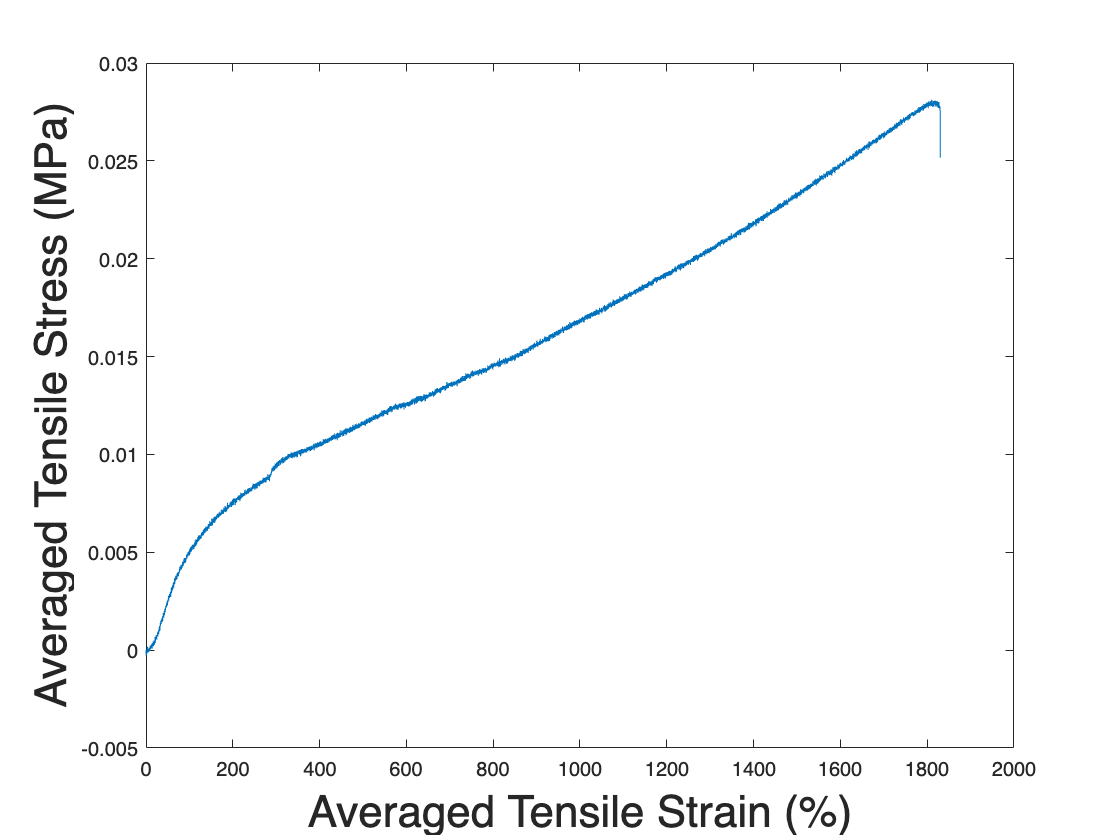

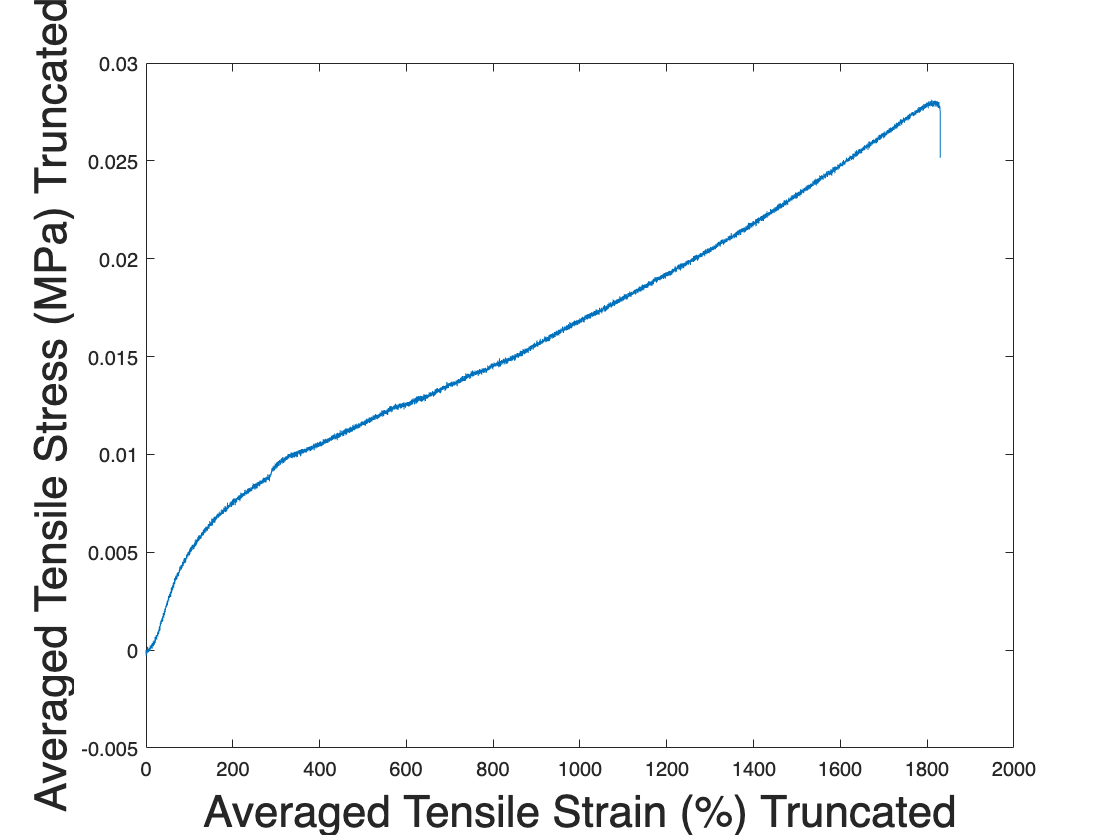

area_under_curve = 29.3240

ans = 54911

index_first_10_percent = 5491

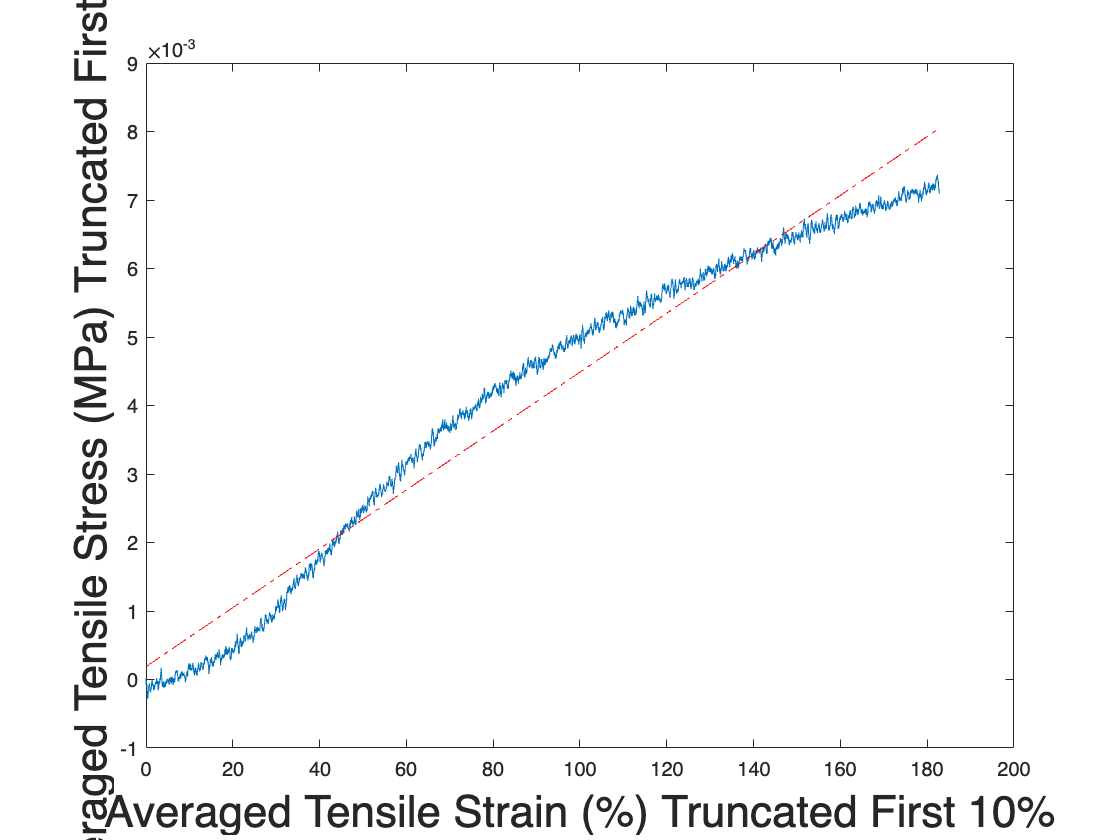

ylimitmax = 0.0281

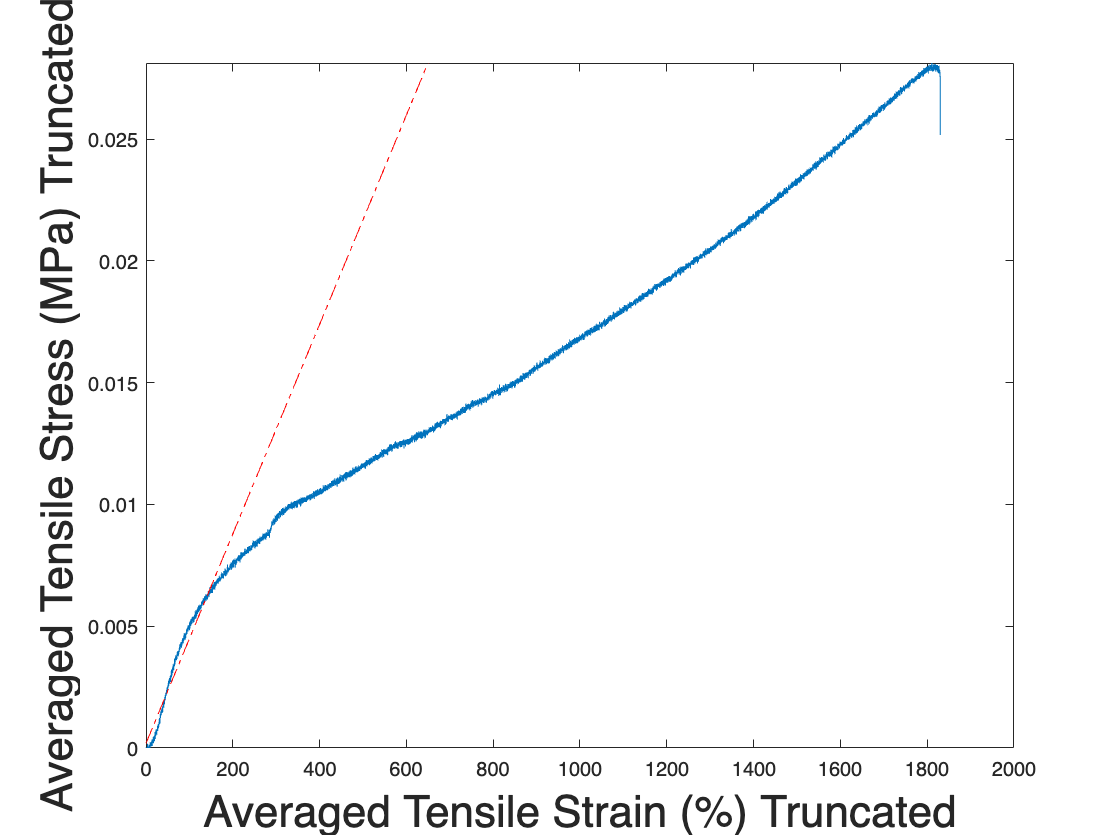

modulus = 4.2990e-05

fracture_energy = 29.3240

ultimate_stress = 0.0281

ultimate_strain = 1.8107e+03

Filename: dummyonesample.csv

File 2 out of 2

area_under_curve = 196.3970

area_under_curve2 = 2.2175

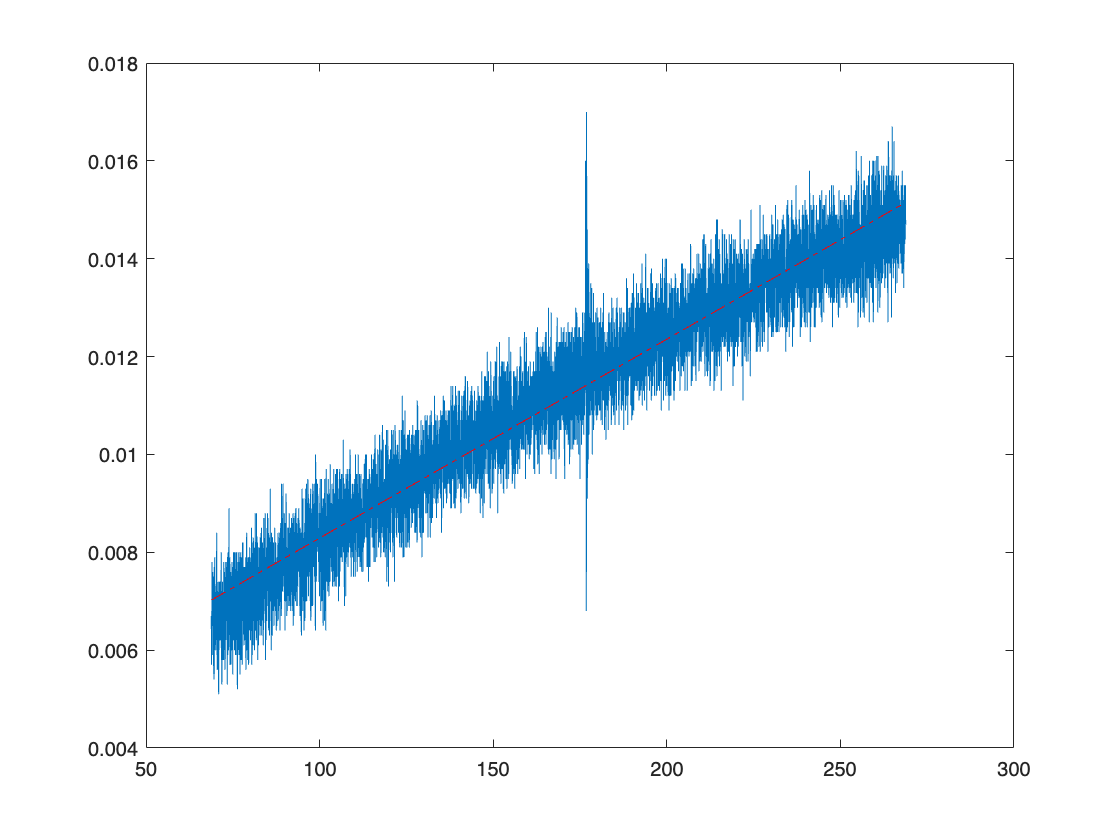

maximum_stress = 0.0780

point_at_which_data_is_dropping = 134393

stress_at_drop = 0.0515

strain_at_drop = 4.4819e+03

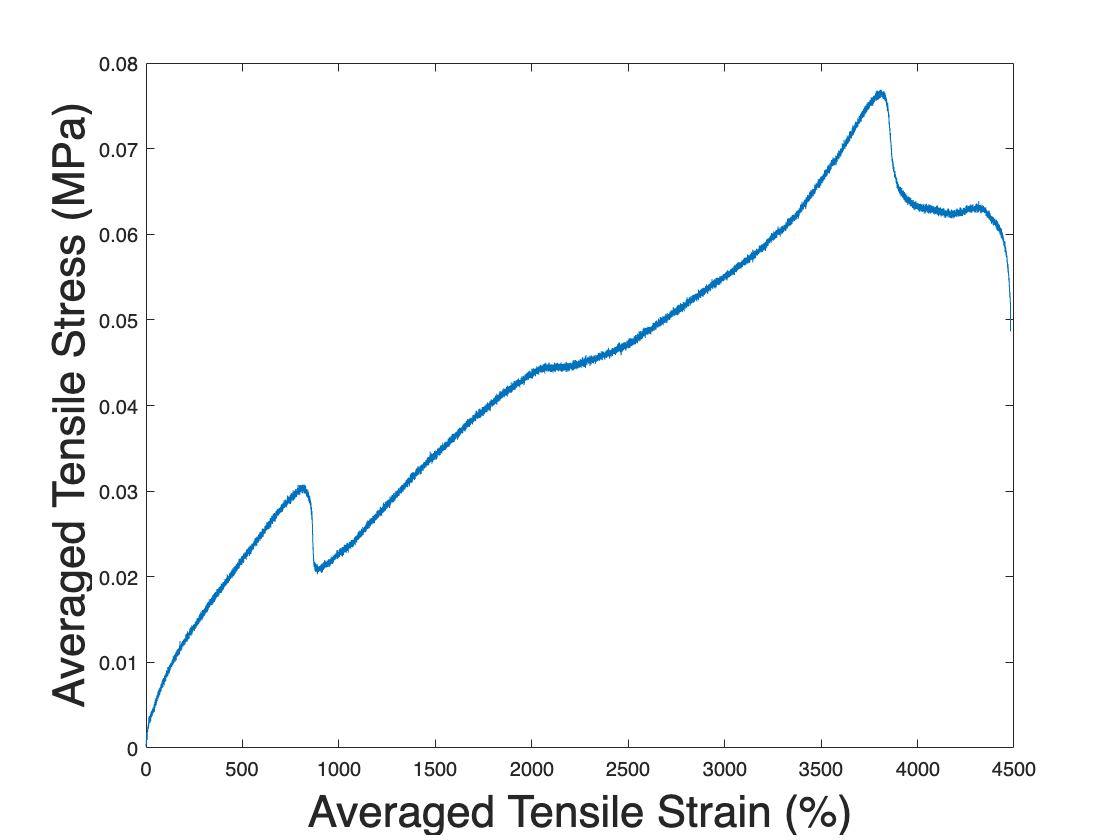

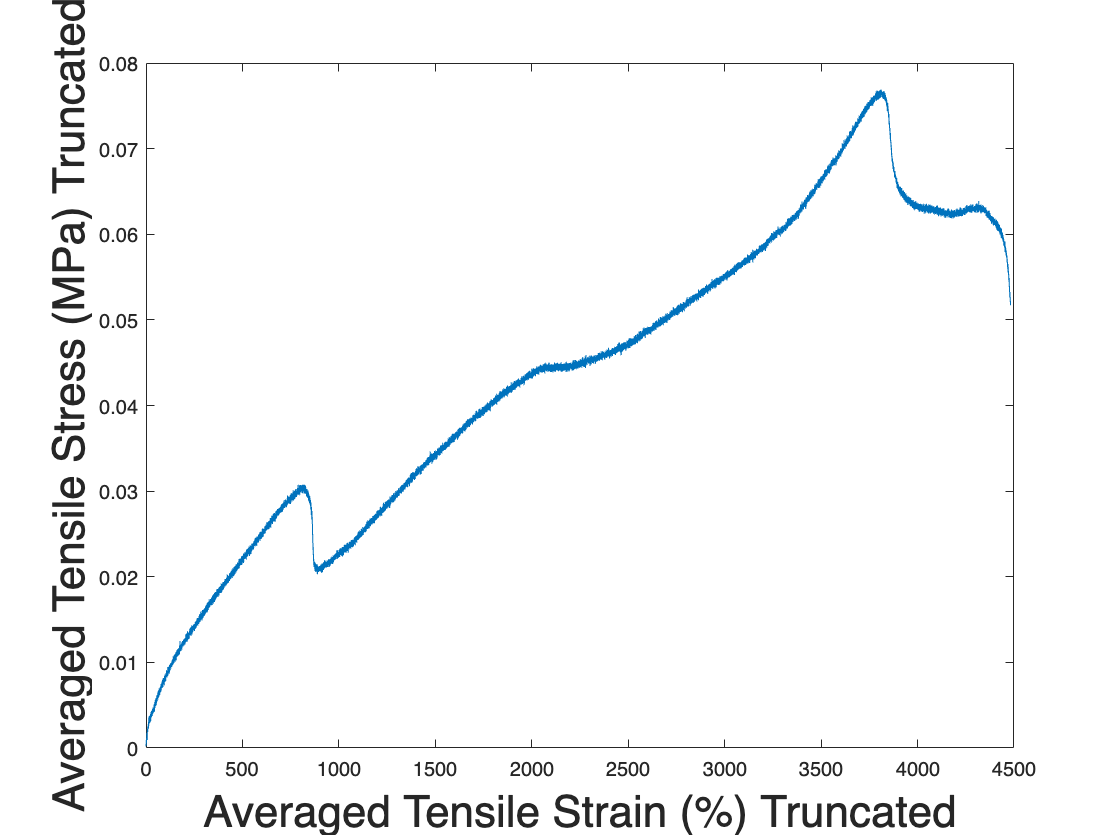

area_under_curve = 196.3822

ans = 134393

index_first_10_percent = 13439

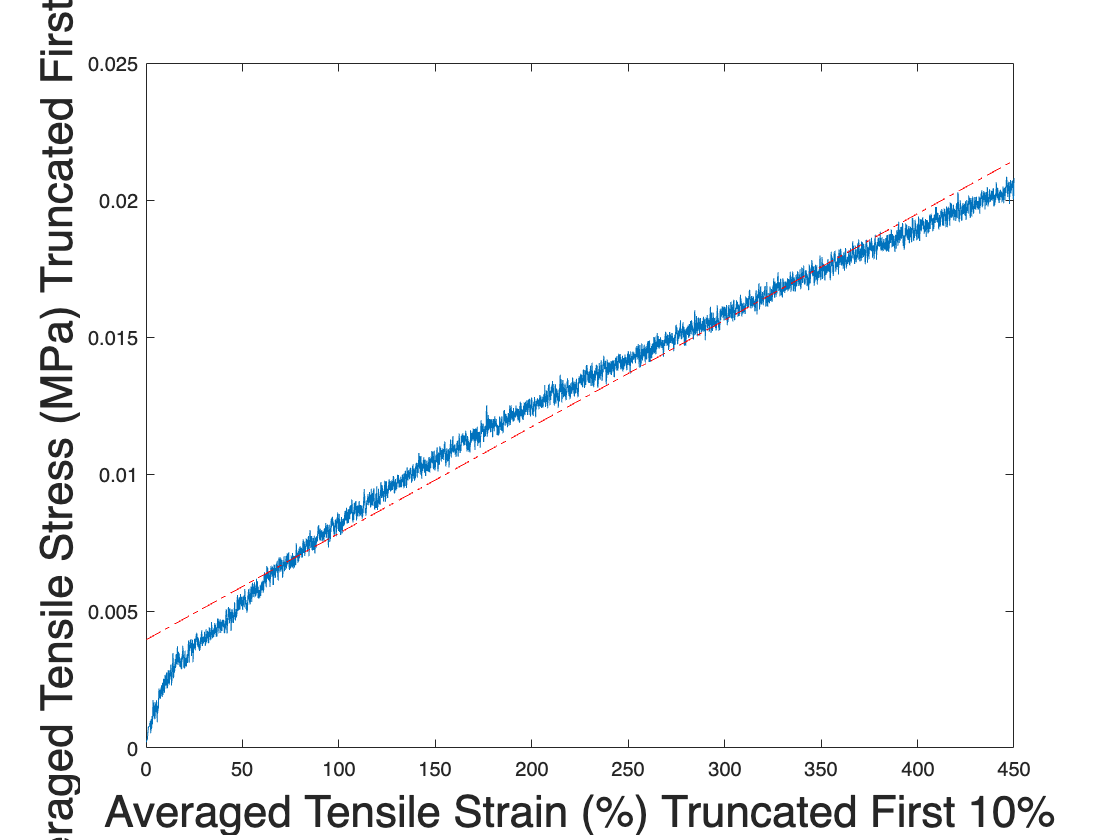

ylimitmax = 0.0769

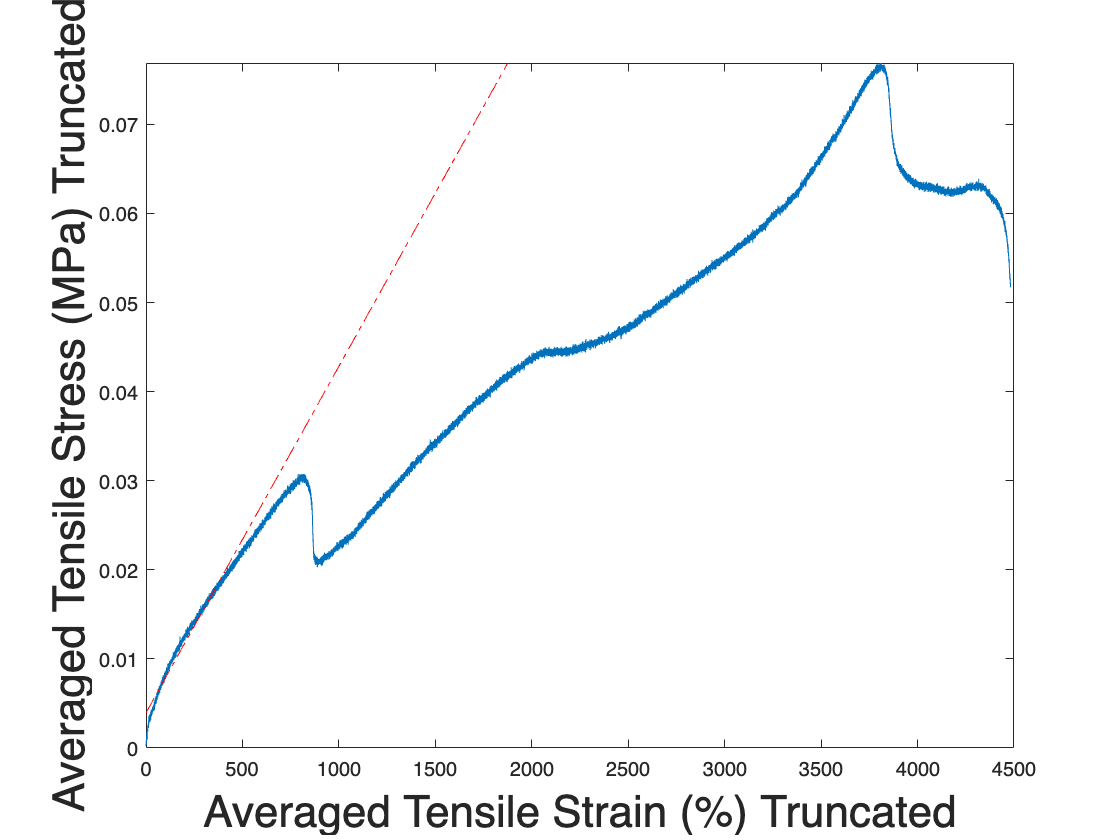

modulus = 3.8884e-05

fracture_energy = 196.3822

ultimate_stress = 0.0769

ultimate_strain = 3.8114e+03

%Initialize matrices that will be used later: 
%Force_N = [];
%Displacement_mm = [];
%Tensile_stress_MPa = []; %in MPa 
%Tensile_strain = []; %in percentage (as opposed to mm) 

%Iterate through all the files: 
for n = 1:length(files)

file1 = csvfiles{n};

%NOTE: If it gives an error that says "Index exceeds the number of array
%elements(0), then that means the current folder is set to the wrong
%folder. Navigate to the correct new folder to fix the error. (Left Menu) 

%Report the filename and file number 
fprintf('Filename: %s',file1)
fprintf('File %d out of %d',n,length(files))
%(note: sprintf creates text/variables together as a string, while fprintf prints it) 

%import the data as both numbers (M) and values including text (C). 
Data_Numerical = readmatrix(file1); %extracts a matrix of data including numerical/decimal values 
Data_Values = readcell(file1); %extracts a matrix of data including text/headers 

num_samples_list = []; %initialize matrix in which to store the sample numbers 
indexes = []; %initialize matrix in which to store the indexes of where the data starts for each sample 
%Split up the data by counting the number of samples that were tested in
%the data 
for z = 1:length(Data_Numerical)
    if isnan(Data_Numerical(z,1)) == 0 %check whether an entry is a sample number, rather than NaN (no data in cell) 
        num_samples_list = [num_samples_list ; Data_Numerical(z,1)]; %store sample numbers in num_samples_list 
        indexes = [indexes ; z]; %store index numbers for start of data set for each sample 
    end
end

    %Report the tables obained from the above "for loop" 
    num_samples_list; %print/report the samples list table 
    indexes; %print / report the indexes table 

%Extract where (in which columns) the desired data is located, so that we
%can pull it out whenever we next need it 
for v = 1:width(Data_Numerical)
    if string(Data_Values(1,v))=="Tensile stress"
        tensile_stress_index = v;
    elseif string(Data_Values(1,v))=="Tensile strain (Displacement)"
        tensile_strain_index = v; 
    end 
end


%%Extract the data itself for a given file: 
for m = 1:length(num_samples_list) %loops through each of the individual samples in a file 
    if not(m==length(num_samples_list)) %if we have not yet looped to the last sample 
        sample_number = m; %extracts what we think the sample number is 
        sample_number_check = Data_Numerical(indexes(m)); %extracts actual sample number from instron data, to double check
        numerical_data = Data_Numerical(indexes(m):indexes(m+1)-1,:); %section out only the data for an individual sample, including the headers (NaN's) 
        %Below, we need to section out only the data (no headers / NaN's)
        %that include the stress and strain. 
        Tensile_stress_MPa = numerical_data(3:end,tensile_stress_index); %in MPa 
        Tensile_strain = numerical_data(3:end,tensile_strain_index); %in % 

        %Plot stress-strain data (note: if you change this, make sure to
        %change the other part of the code equivalent to it below, too) 
        figure
        plot(Tensile_strain,Tensile_stress_MPa); %plot data plot(x_data,y_data) 
        %ax = gca; %use gca for font size for chart 
        %ax.FontSize = 18; %set font for the title of the chart 
        main_title_content = sprintf('Filename: %s',csvfiles{n});
        sub_title_content = sprintf('Sample Number %d of %d',sample_number_check,length(num_samples_list));
        title(main_title_content,sub_title_content,'FontSize',20); 
        ylabel('Tensile Stress (MPa)','FontSize',22); %label y-axis
        xlabel('Tensile Strain (%)','FontSize',22);
        %ylim([-0.03,ylimitmax]) %1 is the max it should be 
        hold on;
        mycustomanalysis(Tensile_strain,Tensile_stress_MPa) %calls a custom data analysis function I made at the end of this code document 

    elseif m==length(num_samples_list) %if we have looped to the last sample 
        %We need a separate chunk of code here because the indexes(m+1)-1
        %does not work, and we need to use "end" instead (extract data up
        %until the end of the sample dataset, rather than up until the next
        %subsequent sample dataset). 
        sample_number = m; %extracts what we think the sample number is 
        sample_number_check = Data_Numerical(indexes(m)); %extracts actual sample number from instron data, to double check 
        numerical_data = Data_Numerical(indexes(m):end,:); %section out only the data for an individual sample, including the headers (NaN's) 
        %Below, we need to section out only the data (no headers / NaN's)
        %that include the stress and strain. 
        Tensile_stress_MPa = numerical_data(3:end,tensile_stress_index); %in MPa 
        Tensile_strain = numerical_data(3:end,tensile_strain_index); %in % 

        %Plot stress-strain data for the last sample  
        figure
        plot(Tensile_strain,Tensile_stress_MPa); %plot data plot(x_data,y_data) 
        %ax = gca; %use gca for font size for chart 
        %ax.FontSize = 18; %set font for the title of the chart 
        main_title_content = sprintf('Filename: %s',csvfiles{n});
        sub_title_content = sprintf('Sample Number %d of %d',sample_number_check,length(num_samples_list));
        title(main_title_content,sub_title_content,'FontSize',20); 
        ylabel('Tensile Stress (MPa)','FontSize',22); %label y-axis
        xlabel('Tensile Strain (%)','FontSize',22);
        %ylim([-0.03,ylimitmax]) %1 is the max it should be 
        hold on;
        mycustomanalysis(Tensile_strain,Tensile_stress_MPa) %calls a custom data analysis function I made at the end of this code document 

    end %end the "if" loop which helps extract the data properly depending on whether it's the last sample or within the first few samples 

end %stop looping through each individual sample in a file 

%old code... 
%Tensile_stress_MPa = numerical_data(:,5); %in MPa 
%Tensile_strain = numerical_data(:,4);


%%Plot Graphs 

%%Old graph plotting code... 
% %Plot stress-strain data  
% figure
% plot(Tensile_strain,Tensile_stress_MPa); %plot data plot(x_data,y_data) 
% %ax = gca; %use gca for font size for chart 
% %ax.FontSize = 18; %set font for the title fo the chart 
% ylabel('Tensile Stress (MPa)','FontSize',22); %label y-axis
% xlabel('Tensile Strain (%)','FontSize',22)
% %ylim([-0.03,ylimitmax]) %1 is the max it should be 
% hold on; 




end %end the loop of interation between the different files 

## Function to plot a graph for an individual dataset

function s = mycustomgraph(Tensile_strain,Tensile_stress_MPa,filename_input,sample_number_input,tot_numberofsamples)

%Plot stress-strain data  
figure
plot(Tensile_strain,Tensile_stress_MPa); %plot data plot(x_data,y_data) 
%ax = gca; %use gca for font size for chart 
%ax.FontSize = 18; %set font for the title fo the chart 
main_title_content = sprintf('Filename: %s',filename_input); 
sub_title_content = sprintf('Sample Number %d of %d',sample_number_input,tot_numberofsamples);
title(main_title_content,sub_title_content,'FontSize',20); 
ylabel('Tensile Stress (MPa)','FontSize',22); %label y-axis
xlabel('Tensile Strain (%)','FontSize',22)
%ylim([-0.03,ylimitmax]) %1 is the max it should be 
hold on; 

%% OLD CODE: 
% %Plot stress-strain data  
% figure
% plot(Tensile_strain,Tensile_stress_MPa); %plot data plot(x_data,y_data) 
% %ax = gca; %use gca for font size for chart 
% %ax.FontSize = 18; %set font for the title fo the chart 
% main_title_content = sprintf('Filename: %s',csvfiles{n}); 
% sub_title_content = sprintf('Sample Number %d of %d',sample_number_check,length(num_samples_list));
% title(main_title_content,sub_title_content,'FontSize',20); 
% ylabel('Tensile Stress (MPa)','FontSize',22); %label y-axis
% xlabel('Tensile Strain (%)','FontSize',22)
% %ylim([-0.03,ylimitmax]) %1 is the max it should be 
% hold on; 

end

## Function To Do Data Analysis (which we call in the above code, and which can be used on an individual dataset) 

function t = mycustomanalysis(Tensile_strain,Tensile_stress_MPa)

%Calculate elastic modulus 

area_under_curve = trapz(Tensile_strain,Tensile_stress_MPa)
%this value looks small but is correct! because the MPa is x 10^-3 in
%reality. 

figure
Tensile_strain2 = Tensile_strain(2000:8000);
Tensile_stress2 = Tensile_stress_MPa(2000:8000);
plot(Tensile_strain2,Tensile_stress2)
area_under_curve2 = trapz(Tensile_strain2,Tensile_stress2)

%fit a curve to the data, using least squares. 
P = polyfit(Tensile_strain2,Tensile_stress2,1);
slope = P(1);
      intercept = P(2);
      yfit = P(1)*Tensile_strain2+P(2);  % P(1) is the slope and P(2) is the intercept
      hold on;
      plot(Tensile_strain2,yfit,'r-.')

      %CODE TO FIND THE PLACE AT WHICH THE DROP OCCURS & store the
      %truncated data 
      Tensile_strain_truncated = []; %initialize tensile strain truncated %%%NEW ADDED AUG 15
      maximum_stress = max(Tensile_stress_MPa)
      for i = 6:length(Tensile_strain)-6 
          if mean(Tensile_stress_MPa(i-5:i)) - mean(Tensile_stress_MPa(i:i+5)) > .002
              point_at_which_data_is_dropping = i
              stress_at_drop = Tensile_stress_MPa(i)
              strain_at_drop = Tensile_strain(i)
              Tensile_stress_MPa_truncated = Tensile_stress_MPa(1:i); 
              Tensile_strain_truncated = Tensile_strain(1:i);
             break
              %then truncate the data there, and end. 
          end
      end

      %Break the code in case it didn't work for this set of data!! 
      if isempty(Tensile_strain_truncated) %If the above loop was unable to find a dropping point
          Tensile_strain_truncated = Tensile_strain
          Tensile_stress_MPa_truncated = Tensile_stress_MPa
          fprintf('Code was unable to truncated data at dropping point. So, all the data was used')
      end

      %Manually average the data every 5 datapoints. 
      %averaged_Tensile_strain = [];
      %averaged_Tensile_stress_MPa = [];
      %for k = 1:length(Tensile_strain)-5 
      %    averaged_Tensile_strain = [ averaged_Tensile_strain ; mean(Tensile_strain(k:k+5))];
      %    averaged_Tensile_stress_MPa = [ averaged_Tensile_stress_MPa ; mean(Tensile_stress_MPa(k:k+5))];
      %end

      %CODE TO FILTER THE DATA 
      %make a ten point moving average filter on the data: 
      B = 1/10*ones(10,1);
      averaged_Tensile_strain = filter(B,1,Tensile_strain);
      averaged_Tensile_stress_MPa = filter(B,1,Tensile_stress_MPa);

%Plot stress-strain data, averaged for every 5 points 
figure
plot(averaged_Tensile_strain,averaged_Tensile_stress_MPa) %plot data plot(x_data,y_data) 
%ax = gca; %use gca for font size for chart 
%ax.FontSize = 18; %set font for the title fo the chart 
ylabel('Averaged Tensile Stress (MPa)','FontSize',22); %label y-axis
xlabel('Averaged Tensile Strain (%)','FontSize',22)
%ylim([-0.03,ylimitmax]) %1 is the max it should be 
hold on; 

C = 1/10*ones(10,1);
      averaged_Tensile_strain_truncated = filter(B,1,Tensile_strain_truncated);
      averaged_Tensile_stress_MPa_truncated = filter(B,1,Tensile_stress_MPa_truncated);

%Plot truncated data 
figure
plot(averaged_Tensile_strain_truncated,averaged_Tensile_stress_MPa_truncated) %plot data plot(x_data,y_data) 
%ax = gca; %use gca for font size for chart 
%ax.FontSize = 18; %set font for the title fo the chart 
ylabel('Averaged Tensile Stress (MPa) Truncated','FontSize',22); %label y-axis
xlabel('Averaged Tensile Strain (%) Truncated','FontSize',22)
%ylim([-0.03,ylimitmax]) %1 is the max it should be 
hold on; 

%Calculate the modulus
area_under_curve = trapz(averaged_Tensile_strain_truncated,averaged_Tensile_stress_MPa_truncated)

%cut off the first 10% of the data 
length(averaged_Tensile_stress_MPa_truncated)
index_first_10_percent = fix(0.10*length(averaged_Tensile_stress_MPa_truncated)) %fix() turns it into an integer. 
first_10_percent_strain = averaged_Tensile_strain_truncated(1:index_first_10_percent);
first_10_percent_stress = averaged_Tensile_stress_MPa_truncated(1:index_first_10_percent);

%Plot first 10% of data 
figure
plot(first_10_percent_strain,first_10_percent_stress) %plot data plot(x_data,y_data) 
%ax = gca; %use gca for font size for chart 
%ax.FontSize = 18; %set font for the title fo the chart 
ylabel('Averaged Tensile Stress (MPa) Truncated First 10%','FontSize',22); %label y-axis
xlabel('Averaged Tensile Strain (%) Truncated First 10%','FontSize',22)
%ylim([-0.03,ylimitmax]) %1 is the max it should be 
hold on; 

%fit a curve to the data, using least squares. 
Fitted_curve = polyfit(first_10_percent_strain,first_10_percent_stress,1);
slope = Fitted_curve(1);
intercept_first10percent = Fitted_curve(2);
yfit_first10percent = Fitted_curve(1)*first_10_percent_strain+Fitted_curve(2);  % Fitted_curve(1) is the slope and Fitted_curve(2) is the intercept
hold on;
      plot(first_10_percent_strain,yfit_first10percent,'r-.')

      %Plot truncated data 
figure
plot(averaged_Tensile_strain_truncated,averaged_Tensile_stress_MPa_truncated) %plot data plot(x_data,y_data) 
%ax = gca; %use gca for font size for chart 
%ax.FontSize = 18; %set font for the title fo the chart 
ylabel('Averaged Tensile Stress (MPa) Truncated','FontSize',22); %label y-axis
xlabel('Averaged Tensile Strain (%) Truncated','FontSize',22)
ylimitmax = max(averaged_Tensile_stress_MPa_truncated) %calculate the maximum of the filtered data so we can set the y-axis limit 
ylim([0,ylimitmax]) %1 is the max it should be 
hold on; 
yfit_modulus = Fitted_curve(1)*averaged_Tensile_strain_truncated+Fitted_curve(2);  % Fitted_curve(1) is the slope and Fitted_curve(2) is the intercept
hold on;
      plot(averaged_Tensile_strain_truncated,yfit_modulus,'r-.')
modulus = Fitted_curve(1) %modulus, in MPa
fracture_energy = trapz(averaged_Tensile_strain_truncated,averaged_Tensile_stress_MPa_truncated) 
ultimate_stress = max(averaged_Tensile_stress_MPa_truncated) %in MPa 

Index=find(averaged_Tensile_stress_MPa_truncated==ultimate_stress,1,'last');
ultimate_strain = averaged_Tensile_strain_truncated(Index) %in percentage units of strain 


end